# Template of Manipulator Short project: Skull tumor surgery

Authors: Ana Siesto Pérez and Xavier Marti Llull

Team:  G11-A

Shared Link with the teacher: [https://drive.matlab.com/sharing/5ad6e326-a326-4433-8939-c068f5f932cd](https://drive.matlab.com/sharing/5ad6e326-a326-4433-8939-c068f5f932cd) 

## The Robotic environment (10%)

Think that later on the enviroment will move to any place in a Univers Reference Frame {U}

Use: 'c = uisetcolor' to chose your prefered colors

### Operating table

It can be raised, lowered, and tilted in any direction, and an  auxiliary table for the tools. Define: Vertices and Faces and use  'patch'  functions to model it. See help patch to find and example.

Think that later on the enviroment will move to any place in a Univers Reference Frame {U}

**Expected results**

### 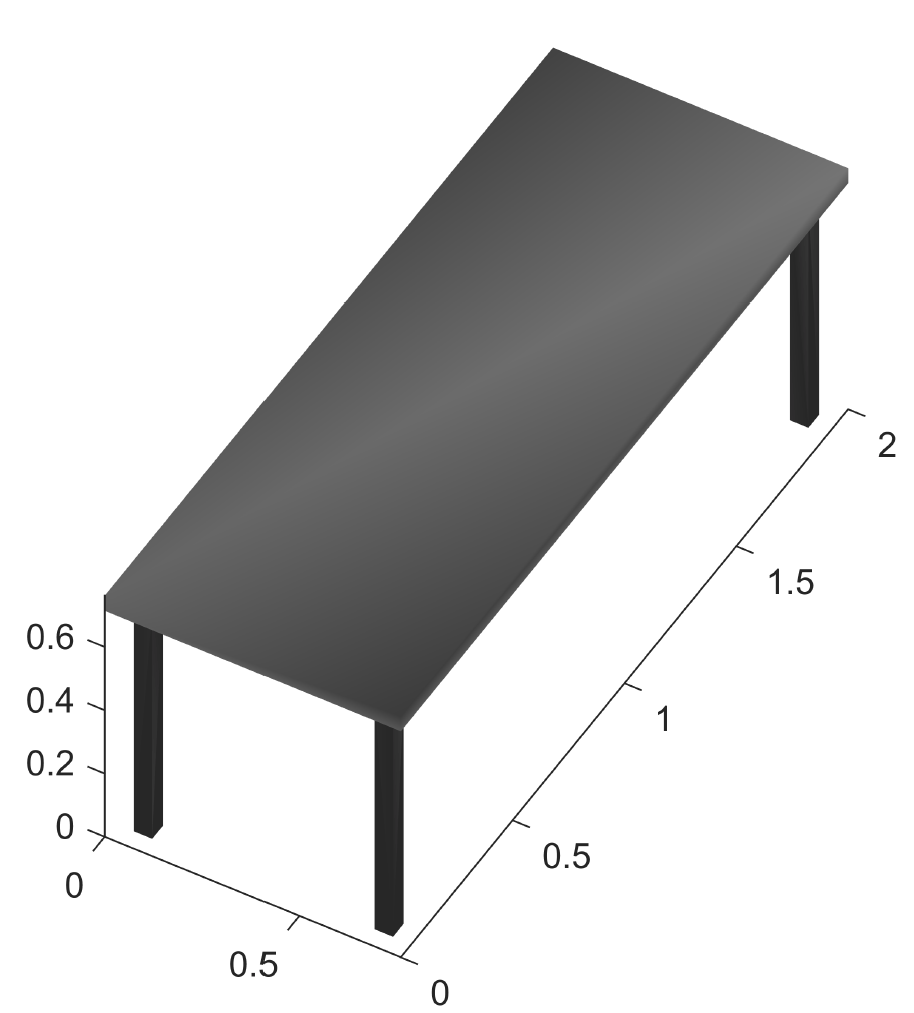

### Cube of reference

% In this section of code we represent the cube that we will use as reference to create all the elements of the scene
clear  
close all
clf
v_cubo = [0 0 0; 1 0 0; 1 1 0; 0 1 0; 0 0 1; 1 0 1; 1 1 1; 0 1 1]

v_cubo =      0     0     0
     1     0     0
     1     1     0
     0     1     0
     0     0     1
     1     0     1
     1     1     1
     0     1     1


f = [1 2 6 5; 2 3 7 6; 3 4 8 7; 4 1 5 8; 1 2 3 4; 5 6 7 8]

f =      1     2     6     5
     2     3     7     6
     3     4     8     7
     4     1     5     8
     1     2     3     4
     5     6     7     8


patch('Vertices', v_cubo, 'Faces', f, 'FaceVertexCData', hsv(6), 'FaceColor', 'black', 'FaceAlpha', 0.3) 
view(30, 45)
axis equal

### Creating the top of the table

% We create all the parts by scaling propperly the initial cube and then we represent
% them separately
H = 2     % x

H = 2

W = 0.9   % y

W = 0.9000

D = 0.08  % z

D = 0.0800

v_tabla = [H 0 0;0 W 0;0 0 D]*v_cubo'

v_tabla =          0    2.0000    2.0000         0         0    2.0000    2.0000         0
         0         0    0.9000    0.9000         0         0    0.9000    0.9000
         0         0         0         0    0.0800    0.0800    0.0800    0.0800


figure
patch('Vertices',v_tabla(1:3,:)','Faces',f,'FaceVertexCData',hsv(6),'FaceColor','black','FaceAlpha',0.3)
grid on
xyzlabel
axis equal
view(3)

### Creating the table's legs

H = 0.1  % x

H = 0.1000

W = 0.1  % y

W = 0.1000

D = 0.8  % z

D = 0.8000

v_pata = [H 0 0;0 W 0;0 0 D]*v_cubo'

v_pata =          0    0.1000    0.1000         0         0    0.1000    0.1000         0
         0         0    0.1000    0.1000         0         0    0.1000    0.1000
         0         0         0         0    0.8000    0.8000    0.8000    0.8000


figure
patch('Vertices',v_pata(1:3,:)','Faces',f,'FaceVertexCData',hsv(6),'FaceColor','black','FaceAlpha',0.3)
view(3)
xyzlabel
axis equal

### Creating a representation of the human body

H = 1.6 % x

H = 1.6000

W = 0.6 % y

W = 0.6000

D = 0.2 % z

D = 0.2000

v_torso = [H 0 0;0 W 0;0 0 D]*v_cubo'

v_torso =          0    1.6000    1.6000         0         0    1.6000    1.6000         0
         0         0    0.6000    0.6000         0         0    0.6000    0.6000
         0         0         0         0    0.2000    0.2000    0.2000    0.2000


figure
patch('Vertices',v_torso(1:3,:)','Faces',f,'FaceVertexCData',hsv(6),'FaceColor',[0.95,0.87,0.7],'FaceAlpha',0.8)
view(3)
xyzlabel
axis equal

### Creating a representation of the human skull

H = 0.15 % x

H = 0.1500

W = 0.20 % y

W = 0.2000

D = 0.17 % z

D = 0.1700

v_craneo = [H 0 0;0 W 0;0 0 D]*v_cubo'

v_craneo =          0    0.1500    0.1500         0         0    0.1500    0.1500         0
         0         0    0.2000    0.2000         0         0    0.2000    0.2000
         0         0         0         0    0.1700    0.1700    0.1700    0.1700


figure
patch('Vertices',v_craneo(1:3,:)','Faces',f,'FaceVertexCData',hsv(6),'FaceColor',[0.89,0.77,0.51],'FaceAlpha',0.8)
view(30,45)
xyzlabel
axis equal

### Creating a tools table

H = 0.3   % x   

H = 0.3000

W = 0.3   % y

W = 0.3000

D = 0.08  % z

D = 0.0800

v_tablaherramientas = [H 0 0;0 W 0;0 0 D]*v_cubo'

v_tablaherramientas =          0    0.3000    0.3000         0         0    0.3000    0.3000         0
         0         0    0.3000    0.3000         0         0    0.3000    0.3000
         0         0         0         0    0.0800    0.0800    0.0800    0.0800


figure
patch('Vertices',v_tablaherramientas(1:3,:)','Faces',f,'FaceVertexCData',hsv(6),'FaceColor','black','FaceAlpha',0.3)
grid on
xyzlabel
axis equal
view(3)

### Transformations

close all
% We move the top of the table to (-0.3, -0.5, 0.8) and then we rotate the
% z axis 60º. Then, we situate all the other elements in function of this and
% take advantage of T_table_0 to represent them with respect to the origin.
T_tabla_0 = transl(-0.3,-0.5,0.8)*trotz(pi/3) % IF YOU WANNA MOVE THE WHOLE SCENE CHANGE THIS LINE

T_tabla_0 =     0.5000   -0.8660         0   -0.3000
    0.8660    0.5000         0   -0.5000
         0         0    1.0000    0.8000
         0         0         0    1.0000


T_pata1_tabla = transl(0.05,0.05,-0.8)

T_pata1_tabla =     1.0000         0         0    0.0500
         0    1.0000         0    0.0500
         0         0    1.0000   -0.8000
         0         0         0    1.0000


T_pata1_0 = T_tabla_0*T_pata1_tabla

T_pata1_0 =     0.5000   -0.8660         0   -0.3183
    0.8660    0.5000         0   -0.4317
         0         0    1.0000         0
         0         0         0    1.0000


T_pata2_tabla = transl(1.85,0.05,-0.8)        

T_pata2_tabla =     1.0000         0         0    1.8500
         0    1.0000         0    0.0500
         0         0    1.0000   -0.8000
         0         0         0    1.0000


T_pata2_0 = T_tabla_0*T_pata2_tabla           

T_pata2_0 =     0.5000   -0.8660         0    0.5817
    0.8660    0.5000         0    1.1271
         0         0    1.0000         0
         0         0         0    1.0000


T_pata3_tabla = transl(0.05,0.75,-0.8)        

T_pata3_tabla =     1.0000         0         0    0.0500
         0    1.0000         0    0.7500
         0         0    1.0000   -0.8000
         0         0         0    1.0000


T_pata3_0 = T_tabla_0*T_pata3_tabla                  

T_pata3_0 =     0.5000   -0.8660         0   -0.9245
    0.8660    0.5000         0   -0.0817
         0         0    1.0000         0
         0         0         0    1.0000


T_pata4_tabla = transl(1.85,0.75,-0.8)        

T_pata4_tabla =     1.0000         0         0    1.8500
         0    1.0000         0    0.7500
         0         0    1.0000   -0.8000
         0         0         0    1.0000


T_pata4_0 = T_tabla_0*T_pata4_tabla

T_pata4_0 =     0.5000   -0.8660         0   -0.0245
    0.8660    0.5000         0    1.4771
         0         0    1.0000         0
         0         0         0    1.0000


T_torso_tabla = transl(0.4,0.15,0.08)

T_torso_tabla =     1.0000         0         0    0.4000
         0    1.0000         0    0.1500
         0         0    1.0000    0.0800
         0         0         0    1.0000


T_torso_0 = T_tabla_0*T_torso_tabla

T_torso_0 =     0.5000   -0.8660         0   -0.2299
    0.8660    0.5000         0   -0.0786
         0         0    1.0000    0.8800
         0         0         0    1.0000


T_craneo_tabla = transl(2.1,0.35,0.08)

T_craneo_tabla =     1.0000         0         0    2.1000
         0    1.0000         0    0.3500
         0         0    1.0000    0.0800
         0         0         0    1.0000


T_craneo_0 = T_tabla_0*T_craneo_tabla

T_craneo_0 =     0.5000   -0.8660         0    0.4469
    0.8660    0.5000         0    1.4937
         0         0    1.0000    0.8800
         0         0         0    1.0000


T_tablaherramientas_tabla = transl(2.5,-0.5,0)

T_tablaherramientas_tabla =     1.0000         0         0    2.5000
         0    1.0000         0   -0.5000
         0         0    1.0000         0
         0         0         0    1.0000


T_tablaherramientas_0 = T_tabla_0*T_tablaherramientas_tabla

T_tablaherramientas_0 =     0.5000   -0.8660         0    1.3830
    0.8660    0.5000         0    1.4151
         0         0    1.0000    0.8000
         0         0         0    1.0000


T_pataherramientas_tablaherramientas = transl(0.1,0.1,-0.8)

T_pataherramientas_tablaherramientas =     1.0000         0         0    0.1000
         0    1.0000         0    0.1000
         0         0    1.0000   -0.8000
         0         0         0    1.0000


T_pataherramientas_0 = T_tablaherramientas_0*T_pataherramientas_tablaherramientas

T_pataherramientas_0 =     0.5000   -0.8660         0    1.3464
    0.8660    0.5000         0    1.5517
         0         0    1.0000         0
         0         0         0    1.0000


### Operating vertices

% It's time to transform the vertexs of every part so they will be
% represented where corresponds. We also agroupate the different sets of
% vertices in a general vector so if we have to move the whole scene it
% will be more practical
v_tabla(4,:) = 1

v_tabla =          0    2.0000    2.0000         0         0    2.0000    2.0000         0
         0         0    0.9000    0.9000         0         0    0.9000    0.9000
         0         0         0         0    0.0800    0.0800    0.0800    0.0800
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


v_tabla_0 = T_tabla_0*v_tabla

v_tabla_0 =    -0.3000    0.7000   -0.0794   -1.0794   -0.3000    0.7000   -0.0794   -1.0794
   -0.5000    1.2321    1.6821   -0.0500   -0.5000    1.2321    1.6821   -0.0500
    0.8000    0.8000    0.8000    0.8000    0.8800    0.8800    0.8800    0.8800
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


v_pata(4,:) = 1

v_pata =          0    0.1000    0.1000         0         0    0.1000    0.1000         0
         0         0    0.1000    0.1000         0         0    0.1000    0.1000
         0         0         0         0    0.8000    0.8000    0.8000    0.8000
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


v_pata1_0 = T_pata1_0*v_pata     

v_pata1_0 =    -0.3183   -0.2683   -0.3549   -0.4049   -0.3183   -0.2683   -0.3549   -0.4049
   -0.4317   -0.3451   -0.2951   -0.3817   -0.4317   -0.3451   -0.2951   -0.3817
         0         0         0         0    0.8000    0.8000    0.8000    0.8000
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


v_pata2_0 = T_pata2_0*v_pata     

v_pata2_0 =     0.5817    0.6317    0.5451    0.4951    0.5817    0.6317    0.5451    0.4951
    1.1271    1.2137    1.2637    1.1771    1.1271    1.2137    1.2637    1.1771
         0         0         0         0    0.8000    0.8000    0.8000    0.8000
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


v_pata3_0 = T_pata3_0*v_pata   

v_pata3_0 =    -0.9245   -0.8745   -0.9611   -1.0111   -0.9245   -0.8745   -0.9611   -1.0111
   -0.0817    0.0049    0.0549   -0.0317   -0.0817    0.0049    0.0549   -0.0317
         0         0         0         0    0.8000    0.8000    0.8000    0.8000
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


v_pata4_0 = T_pata4_0*v_pata

v_pata4_0 =    -0.0245    0.0255   -0.0611   -0.1111   -0.0245    0.0255   -0.0611   -0.1111
    1.4771    1.5637    1.6137    1.5271    1.4771    1.5637    1.6137    1.5271
         0         0         0         0    0.8000    0.8000    0.8000    0.8000
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


v_tablaherramientas(4,:) = 1

v_tablaherramientas =          0    0.3000    0.3000         0         0    0.3000    0.3000         0
         0         0    0.3000    0.3000         0         0    0.3000    0.3000
         0         0         0         0    0.0800    0.0800    0.0800    0.0800
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


v_tablaherramientas_0 = T_tablaherramientas_0*v_tablaherramientas 

v_tablaherramientas_0 =     1.3830    1.5330    1.2732    1.1232    1.3830    1.5330    1.2732    1.1232
    1.4151    1.6749    1.8249    1.5651    1.4151    1.6749    1.8249    1.5651
    0.8000    0.8000    0.8000    0.8000    0.8800    0.8800    0.8800    0.8800
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


v_pataherramientas_0 = T_pataherramientas_0*v_pata

v_pataherramientas_0 =     1.3464    1.3964    1.3098    1.2598    1.3464    1.3964    1.3098    1.2598
    1.5517    1.6383    1.6883    1.6017    1.5517    1.6383    1.6883    1.6017
         0         0         0         0    0.8000    0.8000    0.8000    0.8000
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


v_torso(4,:) = 1

v_torso =          0    1.6000    1.6000         0         0    1.6000    1.6000         0
         0         0    0.6000    0.6000         0         0    0.6000    0.6000
         0         0         0         0    0.2000    0.2000    0.2000    0.2000
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


v_torso_0 = T_torso_0*v_torso

v_torso_0 =    -0.2299    0.5701    0.0505   -0.7495   -0.2299    0.5701    0.0505   -0.7495
   -0.0786    1.3071    1.6071    0.2214   -0.0786    1.3071    1.6071    0.2214
    0.8800    0.8800    0.8800    0.8800    1.0800    1.0800    1.0800    1.0800
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


v_craneo(4,:) = 1

v_craneo =          0    0.1500    0.1500         0         0    0.1500    0.1500         0
         0         0    0.2000    0.2000         0         0    0.2000    0.2000
         0         0         0         0    0.1700    0.1700    0.1700    0.1700
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


v_craneo_0 = T_craneo_0*v_craneo

v_craneo_0 =     0.4469    0.5219    0.3487    0.2737    0.4469    0.5219    0.3487    0.2737
    1.4937    1.6236    1.7236    1.5937    1.4937    1.6236    1.7236    1.5937
    0.8800    0.8800    0.8800    0.8800    1.0500    1.0500    1.0500    1.0500
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


### Plotting parts

% Finally we plot the whole scene and the reference frames of the principal
% objects
figure
hold on
patch('Vertices',v_tabla_0(1:3,:)','Faces',f,'FaceVertexCData',hsv(6),'FaceColor','black','FaceAlpha',0.4)
patch('Vertices',v_pata1_0(1:3,:)','Faces',f,'FaceVertexCData',hsv(6),'FaceColor','black','FaceAlpha',0.4)
patch('Vertices',v_pata2_0(1:3,:)','Faces',f,'FaceVertexCData',hsv(6),'FaceColor','black','FaceAlpha',0.4)
patch('Vertices',v_pata3_0(1:3,:)','Faces',f,'FaceVertexCData',hsv(6),'FaceColor','black','FaceAlpha',0.4)
patch('Vertices',v_pata4_0(1:3,:)','Faces',f,'FaceVertexCData',hsv(6),'FaceColor','black','FaceAlpha',0.4)
patch('Vertices',v_tablaherramientas_0(1:3,:)','Faces',f,'FaceVertexCData',hsv(6),'FaceColor','black','FaceAlpha',0.4)
patch('Vertices',v_pataherramientas_0(1:3,:)','Faces',f,'FaceVertexCData',hsv(6),'FaceColor','black','FaceAlpha',0.4)
patch('Vertices',v_torso_0(1:3,:)','Faces',f,'FaceVertexCData',hsv(6),'FaceColor',[0.95,0.87,0.7],'FaceAlpha',0.8)
patch('Vertices',v_craneo_0(1:3,:)','Faces',f,'FaceVertexCData',hsv(6),'FaceColor',[0.89,0.77,0.51],'FaceAlpha',0.8)
view(30,45)
grid on
xyzlabel
axis equal
axis([-2.5 2.5 -1.5 3.5 0.0 3.5])

### Reference frames

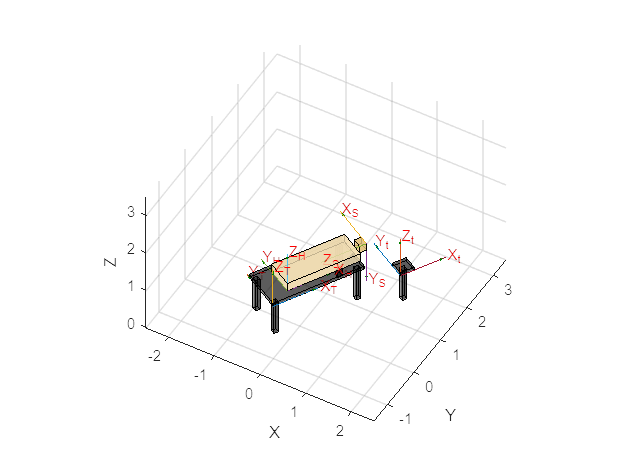

trplot(T_tabla_0,'frame','T' ,'color', 'red','arrow','width',0.4)
trplot(T_torso_0,'frame','H' ,'color', 'red','arrow','width',0.4)
trplot(T_tablaherramientas_0,'frame','t','color','red','arrow','width',0.4)
trplot(T_craneo_0*transl(0.15,0,0.17)*trotz(pi/2)*trotx(-pi/2),'frame','S','color','red','arrow','width',0.4)

### 3D model of a human body 

Situate the human model on the operating table. 

**Expected results**

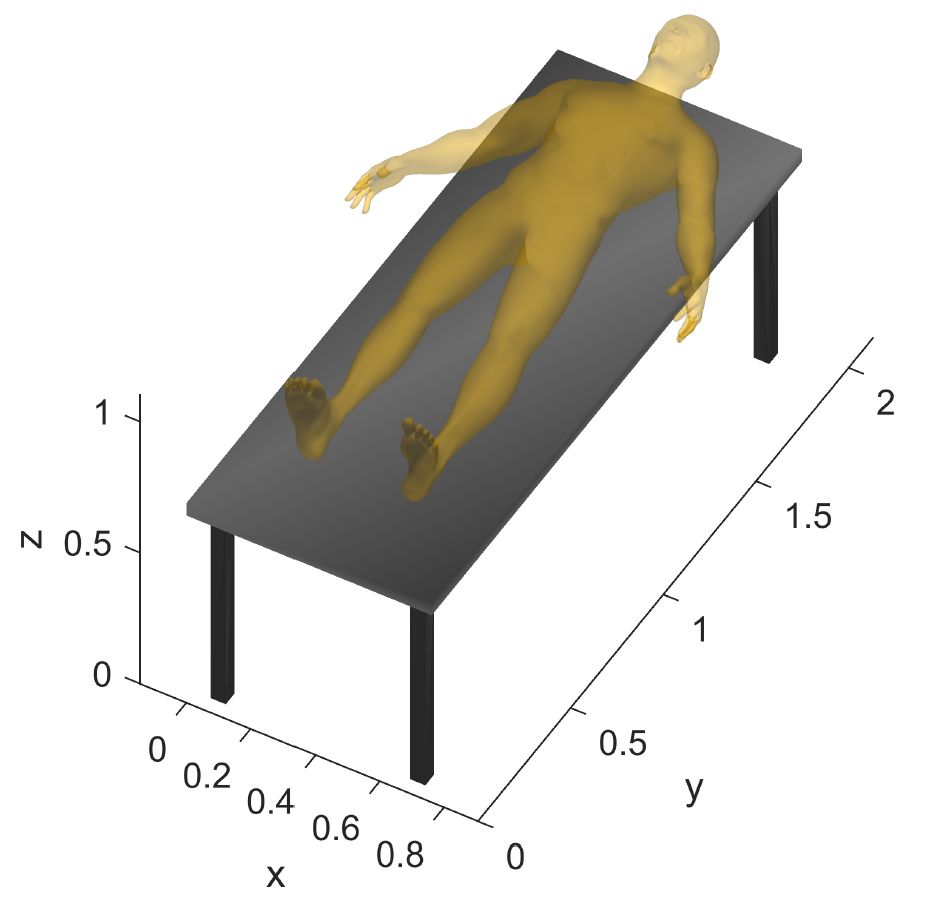

close all
% We load the human model to plot it together with the other elements
Human = load('F_V_HumanBody.mat')

Human = struct with fields:
    Fh: [48918×3 double]
    Vh: [24461×3 double]


v_humano = Human.Vh'

v_humano =    -0.1143   -0.1268   -0.1191   -0.1107   -0.1146   -0.1083   -0.1237   -0.1162   -0.1266   -0.1180   -0.1287   -0.1198   -0.1081   -0.1090   -0.0993   -0.1103   -0.1003   -0.1119   -0.1018   -0.1139   -0.1039   -0.1162   -0.1064   -0.0934   -0.0913   -0.0960   -0.1253   -0.1277   -0.1191   -0.1233   -0.1096   -0.1215   -0.1304   -0.1318   -0.0899   -0.0890   -0.0780   -0.0887   -0.0782   -0.0989   -0.0891   -0.0993   -0.0783   -0.0791   -0.0682   -0.0675   -0.0672   -0.1009   -0.0917   -0.1030
    0.1432    0.1385    0.1450    0.1474    0.1484    0.1504    0.1452    0.1491    0.1462    0.1502    0.1476    0.1513    0.1521    0.1534    0.1560    0.1544    0.1569    0.1551    0.1574    0.1555    0.1574    0.1552    0.1567    0.1589    0.1593    0.1577    0.1532    0.1528    0.1543    0.1530    0.1553    0.1523    0.1489    0.1500    0.1590    0.1582    0.1585    0.1569    0.1597    0.1547    0.1552    0.1529    0.1567    0.1605    0.1611    0.1602    0.1589    0.1504    0.14

v_humano(4,:) = 1

v_humano =    -0.1143   -0.1268   -0.1191   -0.1107   -0.1146   -0.1083   -0.1237   -0.1162   -0.1266   -0.1180   -0.1287   -0.1198   -0.1081   -0.1090   -0.0993   -0.1103   -0.1003   -0.1119   -0.1018   -0.1139   -0.1039   -0.1162   -0.1064   -0.0934   -0.0913   -0.0960   -0.1253   -0.1277   -0.1191   -0.1233   -0.1096   -0.1215   -0.1304   -0.1318   -0.0899   -0.0890   -0.0780   -0.0887   -0.0782   -0.0989   -0.0891   -0.0993   -0.0783   -0.0791   -0.0682   -0.0675   -0.0672   -0.1009   -0.0917   -0.1030
    0.1432    0.1385    0.1450    0.1474    0.1484    0.1504    0.1452    0.1491    0.1462    0.1502    0.1476    0.1513    0.1521    0.1534    0.1560    0.1544    0.1569    0.1551    0.1574    0.1555    0.1574    0.1552    0.1567    0.1589    0.1593    0.1577    0.1532    0.1528    0.1543    0.1530    0.1553    0.1523    0.1489    0.1500    0.1590    0.1582    0.1585    0.1569    0.1597    0.1547    0.1552    0.1529    0.1567    0.1605    0.1611    0.1602    0.1589    0.1504    0.14

T_humano_tabla = transl(0.45,0.45,0.205)*trotx(-pi/2)*troty(pi/2)

T_humano_tabla =          0         0    1.0000    0.4500
   -1.0000         0         0    0.4500
         0   -1.0000         0    0.2050
         0         0         0    1.0000


T_humano_0 = T_tabla_0*T_humano_tabla

T_humano_0 =     0.8660         0    0.5000   -0.4647
   -0.5000         0    0.8660    0.1147
         0   -1.0000         0    1.0050
         0         0         0    1.0000


v_humano_0 = T_humano_0*v_humano

v_humano_0 =     0.0917    0.0829    0.0940    0.0997    0.1005    0.1058    0.0934    0.1019    0.0947    0.1040    0.0969    0.1066    0.1098    0.1133    0.1229    0.1165    0.1268    0.1196    0.1303    0.1224    0.1335    0.1247    0.1361    0.1451    0.1415    0.1481    0.1141    0.1155    0.1262    0.1119    0.1380    0.1093    0.0995    0.1022    0.1375    0.1331    0.1382    0.1282    0.1435    0.1186    0.1227    0.1137    0.1324    0.1484    0.1591    0.1538    0.1482    0.1076    0.1099    0.1006
    1.3072    1.3168    1.3207    1.3138    1.3229    1.3195    1.3288    1.3285    1.3369    1.3358    1.3448    1.3438    1.3261    1.3338    1.3311    1.3420    1.3399    1.3506    1.3490    1.3593    1.3585    1.3680    1.3681    1.3576    1.3473    1.3681    1.3677    1.3751    1.3765    1.3599    1.3778    1.3519    1.3527    1.3602    1.3374    1.3280    1.3149    1.3190    1.3246    1.3228    1.3104    1.3151    1.3056    1.3347    1.3317    1.3210    1.3107    1.3076    1.

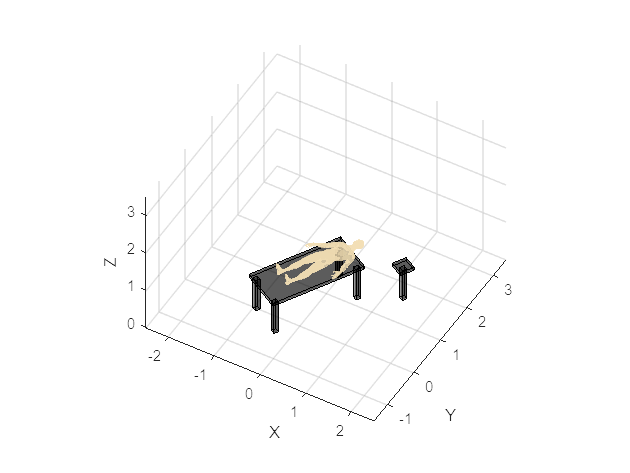

figure
hold on
patch('Vertices',v_tabla_0(1:3,:)','Faces',f,'FaceVertexCData',hsv(6),'FaceColor','black','FaceAlpha',0.4)
patch('Vertices',v_pata1_0(1:3,:)','Faces',f,'FaceVertexCData',hsv(6),'FaceColor','black','FaceAlpha',0.4)
patch('Vertices',v_pata2_0(1:3,:)','Faces',f,'FaceVertexCData',hsv(6),'FaceColor','black','FaceAlpha',0.4)
patch('Vertices',v_pata3_0(1:3,:)','Faces',f,'FaceVertexCData',hsv(6),'FaceColor','black','FaceAlpha',0.4)
patch('Vertices',v_pata4_0(1:3,:)','Faces',f,'FaceVertexCData',hsv(6),'FaceColor','black','FaceAlpha',0.4)
patch('Vertices',v_tablaherramientas_0(1:3,:)','Faces',f,'FaceVertexCData',hsv(6),'FaceColor','black','FaceAlpha',0.4)
patch('Vertices',v_pataherramientas_0(1:3,:)','Faces',f,'FaceVertexCData',hsv(6),'FaceColor','black','FaceAlpha',0.4)
patch('Vertices',v_humano_0(1:3,:)','Faces',Human.Fh,'FaceVertexCData',hsv(6),'FaceColor',[0.95,0.87,0.7], 'Edgecolor', 'none', 'FaceAlpha',0.8)
view(30,45)
grid on
xyzlabel
axis equal
axis([-2.5 2.5 -1.5 3.5 0.0 3.5])

### Fiducials

The Radiology Department before to take a Computer Tomography (CT) of the brain, fix three fiducials in the head of the patient for registering purpose,  visit: [https://en.wikipedia.org/wiki/Fiducial](https://en.wikipedia.org/wiki/Fiducial)

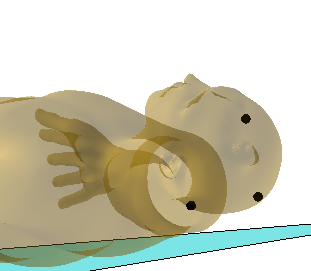

### Dicom image vs Image Reference frame {I}

Get familiar with Dicom Images, Visit: https://www.imaios.com/en/Imaios-Dicom-Viewer#!

Use a container Box of the skull  to infer the Image Reference Frame {I}

See:  6_Plot_Box_Cone.mlx and 7_Help_Image_RF_Containig_Box.fig to inspire yourselt 

**Expected results**

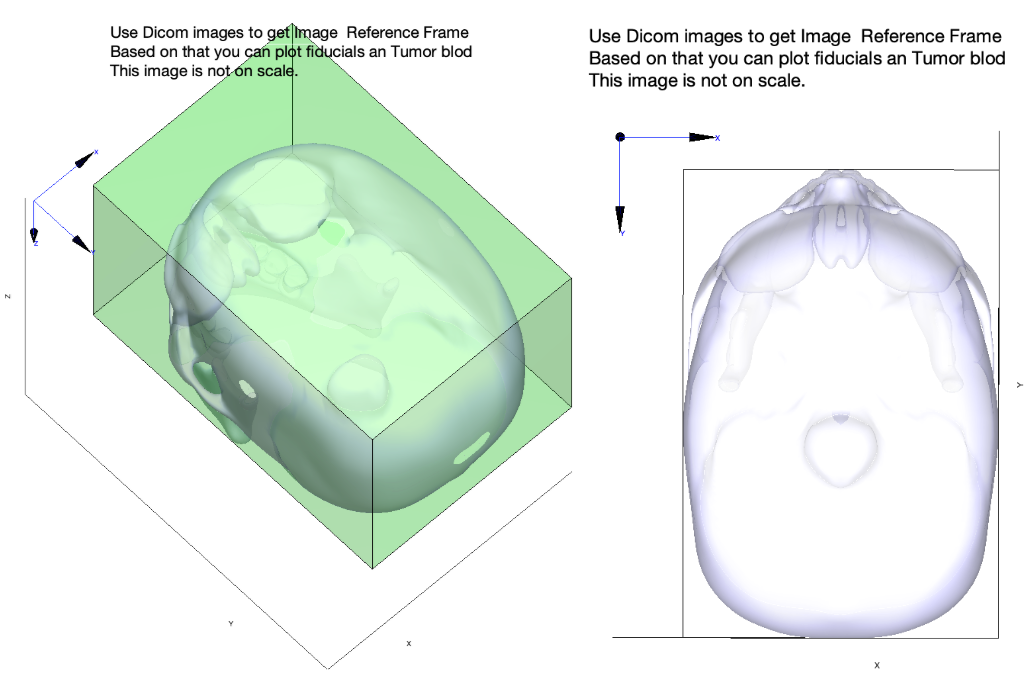

close all
% We represent an scaled box with we can work with together with dicomm image's
% coordinates and load an skull to place it in, and then we rotate them to
% place them as they will be placed in the surgery
H = 2.55

H = 2.5500

W = 2.55

W = 2.5500

D = 1.568

D = 1.5680

v_contenedor = [H 0 0; 0 W 0; 0 0 D]*v_cubo'

v_contenedor =          0    2.5500    2.5500         0         0    2.5500    2.5500         0
         0         0    2.5500    2.5500         0         0    2.5500    2.5500
         0         0         0         0    1.5680    1.5680    1.5680    1.5680


Skull = load("F_V_Skull.mat")

Skull = struct with fields:
    Fs: [80016×3 double]
    Vs: [40062×3 double]


H = 9.7

H = 9.7000

W = 9.7

W = 9.7000

D = 9.7

D = 9.7000

v_craneo = [H 0 0; 0 W 0; 0 0 D]*Skull.Vs'

v_craneo =    -0.1231   -0.0939   -0.0913   -0.1202   -0.0634   -0.0615   -0.0596   -0.0890   -0.1179   -0.0320   -0.0310   -0.0000   -0.0000         0   -0.0299   -0.0290   -0.0583         0         0   -0.0285   -0.0576   -0.0882   -0.1178   -0.0880   -0.1229   -0.3463   -0.3407   -0.3455   -0.3515   -0.3350   -0.3397   -0.3452   -0.3512   -0.3574   -0.3268   -0.3320   -0.3169   -0.3226   -0.3283   -0.3376   -0.3429   -0.3508   -0.3336   -0.3388   -0.3484   -0.3566   -0.3572   -0.3637   -0.3635   -0.3704
   -1.1068   -1.1194   -1.1144   -1.1024   -1.1296   -1.1242   -1.1172   -1.1079   -1.0965   -1.1367   -1.1311   -1.1394   -1.1338   -1.1261   -1.1236   -1.1167   -1.1108   -1.1189   -1.1137   -1.1119   -1.1067   -1.1018   -1.0907   -1.0982   -1.0845   -0.8026   -0.8026   -0.7817   -0.7820   -0.8027   -0.7817   -0.7613   -0.7614   -0.7619   -0.8016   -0.7807   -0.7994   -0.7789   -0.7586   -0.7604   -0.7403   -0.7415   -0.7384   -0.7187   -0.7209   -0.7225   -0.7419   -0.7426   -0.72

v_craneo(4,:) = 1

v_craneo =    -0.1231   -0.0939   -0.0913   -0.1202   -0.0634   -0.0615   -0.0596   -0.0890   -0.1179   -0.0320   -0.0310   -0.0000   -0.0000         0   -0.0299   -0.0290   -0.0583         0         0   -0.0285   -0.0576   -0.0882   -0.1178   -0.0880   -0.1229   -0.3463   -0.3407   -0.3455   -0.3515   -0.3350   -0.3397   -0.3452   -0.3512   -0.3574   -0.3268   -0.3320   -0.3169   -0.3226   -0.3283   -0.3376   -0.3429   -0.3508   -0.3336   -0.3388   -0.3484   -0.3566   -0.3572   -0.3637   -0.3635   -0.3704
   -1.1068   -1.1194   -1.1144   -1.1024   -1.1296   -1.1242   -1.1172   -1.1079   -1.0965   -1.1367   -1.1311   -1.1394   -1.1338   -1.1261   -1.1236   -1.1167   -1.1108   -1.1189   -1.1137   -1.1119   -1.1067   -1.1018   -1.0907   -1.0982   -1.0845   -0.8026   -0.8026   -0.7817   -0.7820   -0.8027   -0.7817   -0.7613   -0.7614   -0.7619   -0.8016   -0.7807   -0.7994   -0.7789   -0.7586   -0.7604   -0.7403   -0.7415   -0.7384   -0.7187   -0.7209   -0.7225   -0.7419   -0.7426   -0.72

T_craneo_contenedor = transl(1.25,1.3,-0.50)

T_craneo_contenedor =     1.0000         0         0    1.2500
         0    1.0000         0    1.3000
         0         0    1.0000   -0.5000
         0         0         0    1.0000


v_craneo_0 = T_craneo_contenedor*v_craneo

v_craneo_0 =     1.1269    1.1561    1.1587    1.1298    1.1866    1.1885    1.1904    1.1610    1.1321    1.2180    1.2190    1.2500    1.2500    1.2500    1.2201    1.2210    1.1917    1.2500    1.2500    1.2215    1.1924    1.1618    1.1322    1.1620    1.1271    0.9037    0.9093    0.9045    0.8985    0.9150    0.9103    0.9048    0.8988    0.8926    0.9232    0.9180    0.9331    0.9274    0.9217    0.9124    0.9071    0.8992    0.9164    0.9112    0.9016    0.8934    0.8928    0.8863    0.8865    0.8796
    0.1932    0.1806    0.1856    0.1976    0.1704    0.1758    0.1828    0.1921    0.2035    0.1633    0.1689    0.1606    0.1662    0.1739    0.1764    0.1833    0.1892    0.1811    0.1863    0.1881    0.1933    0.1982    0.2093    0.2018    0.2155    0.4974    0.4974    0.5183    0.5180    0.4973    0.5183    0.5387    0.5386    0.5381    0.4984    0.5193    0.5006    0.5211    0.5414    0.5396    0.5597    0.5585    0.5616    0.5813    0.5791    0.5775    0.5581    0.5574    0.

figure
hold on
patch('Vertices', v_contenedor(1:3,:)', 'Faces', f, 'FaceVertexCData', hsv(6), 'FaceColor', [0 1 0], 'FaceAlpha', 0.3) 
patch('Vertices',v_craneo_0(1:3,:)','Faces',Skull.Fs,'FaceVertexCData',hsv(6),'FaceColor',[0.5 0.5 0.5], 'Edgecolor', 'none', 'FaceAlpha',0.8)
view(30, 45)
grid on
axis equal
axis([-1.0 4.0 -1.0 3.0 -1.0 4.0])
T_contenedor_0 = transl(3,-0.2,2)*trotz(pi)*trotx(pi)

T_contenedor_0 =    -1.0000         0         0    3.0000
         0    1.0000         0   -0.2000
         0         0   -1.0000    2.0000
         0         0         0    1.0000


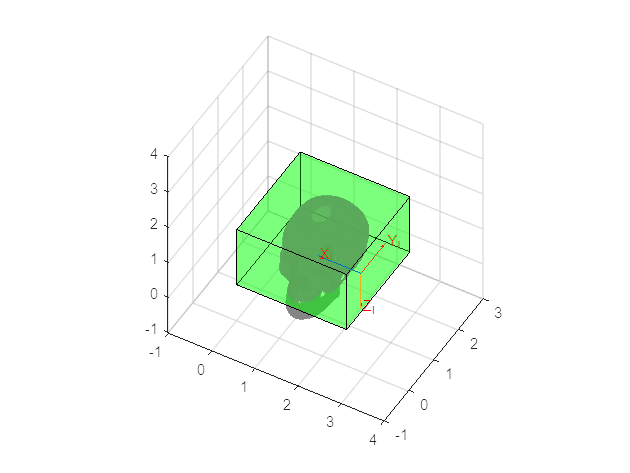

trplot(T_contenedor_0,'frame','I' ,'color', 'r','arrow','width',0.4)

### Fiducials wrt {I}

Use the Dicom images to place the fiducial relative to Image Reference Frame {I}.

See: 5_Skull_pose_estimation.mlx and use the skull to make the exercise.

**Expected results**

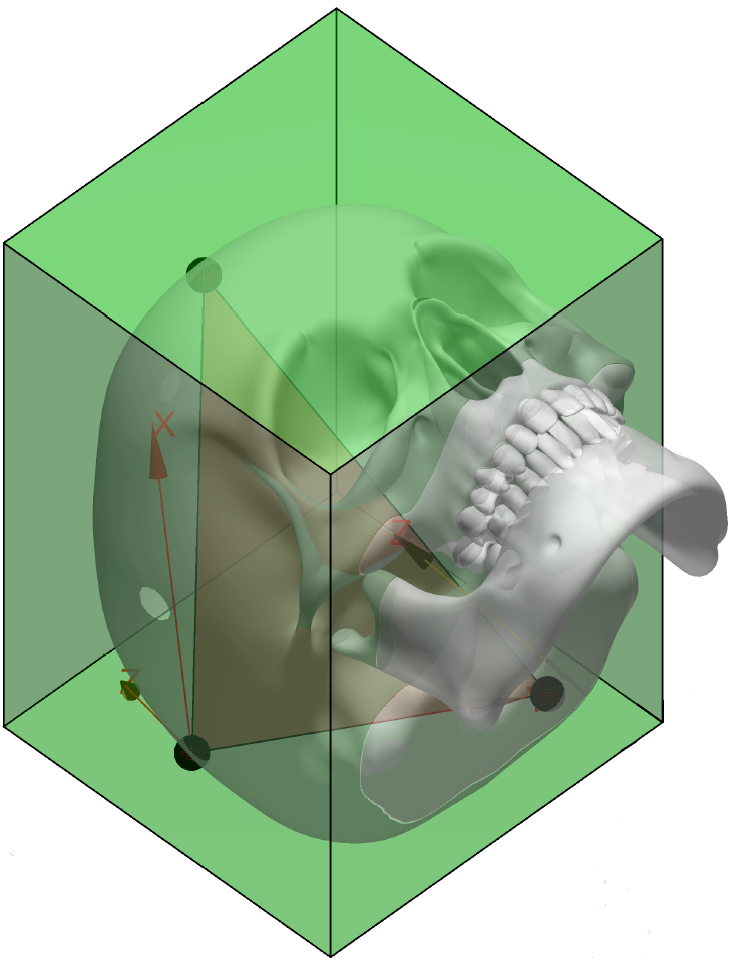

close all

v_contenedor(4,:) = 1

v_contenedor =          0    2.5500    2.5500         0         0    2.5500    2.5500         0
         0         0    2.5500    2.5500         0         0    2.5500    2.5500
         0         0         0         0    1.5680    1.5680    1.5680    1.5680
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


T_contenedor_0 = trotx(-pi/2)

T_contenedor_0 = 4×4
     1     0     0     0
     0     0     1     0
     0    -1     0     0
     0     0     0     1


v_contenedor_0 = T_contenedor_0 * v_contenedor

v_contenedor_0 = 4×8
         0    2.5500    2.5500         0         0    2.5500    2.5500         0
         0         0         0         0    1.5680    1.5680    1.5680    1.5680
         0         0   -2.5500   -2.5500         0         0   -2.5500   -2.5500
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


T_craneo_contenedor = transl(1.25,1.35,-0.50)

T_craneo_contenedor = 4×4
    1.0000         0         0    1.2500
         0    1.0000         0    1.3500
         0         0    1.0000   -0.5000
         0         0         0    1.0000


T_craneo_0 = T_contenedor_0 * T_craneo_contenedor

T_craneo_0 = 4×4
    1.0000         0         0    1.2500
         0         0    1.0000   -0.5000
         0   -1.0000         0   -1.3500
         0         0         0    1.0000


v_craneo_0 = T_craneo_0*v_craneo

v_craneo_0 = 4×40062
    1.1269    1.1561    1.1587    1.1298    1.1866    1.1885    1.1904    1.1610    1.1321    1.2180    1.2190    1.2500    1.2500    1.2500    1.2201    1.2210    1.1917    1.2500    1.2500    1.2215    1.1924    1.1618    1.1322    1.1620    1.1271    0.9037    0.9093    0.9045    0.8985    0.9150
   -0.4179   -0.4201   -0.3930   -0.3915   -0.4225   -0.3951   -0.3641   -0.3622   -0.3615   -0.4244   -0.3969   -0.4253   -0.3978   -0.3669   -0.3660   -0.3338   -0.3318   -0.3348   -0.3033   -0.3024   -0.3000   -0.3293   -0.3293   -0.2967   -0.2930   -0.1977   -0.1802   -0.1739   -0.1893   -0.1623
   -0.2432   -0.2306   -0.2356   -0.2476   -0.2204   -0.2258   -0.2328   -0.2421   -0.2535   -0.2133   -0.2189   -0.2106   -0.2162   -0.2239   -0.2264   -0.2333   -0.2392   -0.2311   -0.2363   -0.2381   -0.2433   -0.2482   -0.2593   -0.2518   -0.2655   -0.5474   -0.5474   -0.5683   -0.5680   -0.5473
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.


% We move the fiducials to the coordinates that we have analyzed in the
% dicomm images
triangulo_fiducials = [2.55-1.22 1.568-0.252 -0.62; 2.55-0.7 1.568-1.12 -2.14; 2.55-1.86 1.568-0.658 -2.10]

triangulo_fiducials = 3×3
    1.3300    1.3160   -0.6200
    1.8500    0.4480   -2.1400
    0.6900    0.9100   -2.1000


caras_triangulo_fiducials = [1 2 3]

caras_triangulo_fiducials = 1×3
     1     2     3


[X,Y,Z] = sphere;
r=0.08

r = 0.0800

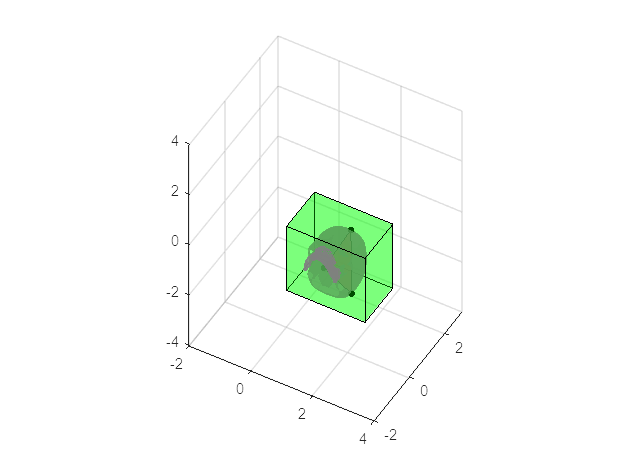


figure
hold on
surf(X*r+2.55-1.22,Y*r+1.568-0.252,Z*r-0.62,'FaceColor',[1 0 0])
surf(X*r+2.55-0.70,Y*r+1.568-1.12,Z*r-2.14,'FaceColor',[1 0 0])
surf(X*r+2.55-1.86,Y*r+1.568-0.658,Z*r-2.10,'FaceColor',[1 0 0])
patch('Vertices', v_contenedor_0(1:3,:)', 'Faces', f, 'FaceVertexCData', hsv(6), 'FaceColor', [0 1 0], 'FaceAlpha', 0.3)
patch('Vertices',v_craneo_0(1:3,:)','Faces',Skull.Fs,'FaceVertexCData',hsv(6),'FaceColor',[0.5 0.5 0.5], 'Edgecolor', 'none', 'FaceAlpha',0.8)
patch('Vertices',triangulo_fiducials,'Faces',caras_triangulo_fiducials,'FaceColor', [1 0 0], 'FaceAlpha', 0.3)
view(30, 45)
grid on
axis equal
axis([-2.0 4.0 -2.0 3.0 -4.0 4.0])

### Tumor points wrt {I}

Use the Dicom images to get the points of the outer perimeter of the tumor relative to Image Reference Frame {I}.

You can simplify the tumor information by defining the center of mass and estimate an equivalent diameter.

**Expected results**

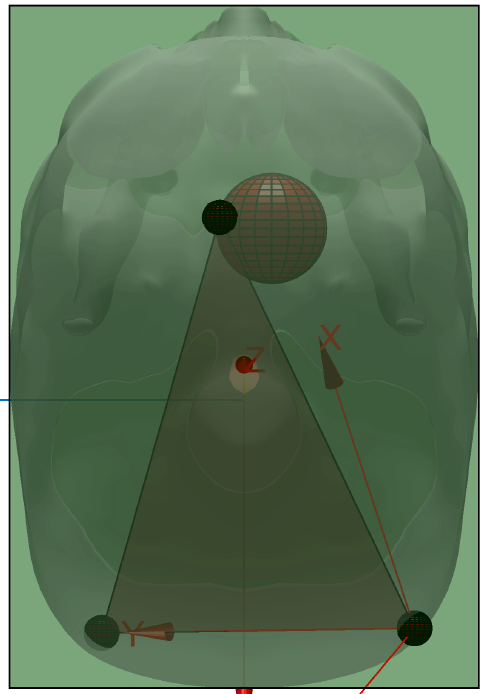

close all
% We place the tumor in scale
r2 = 0.145

r2 = 0.1450

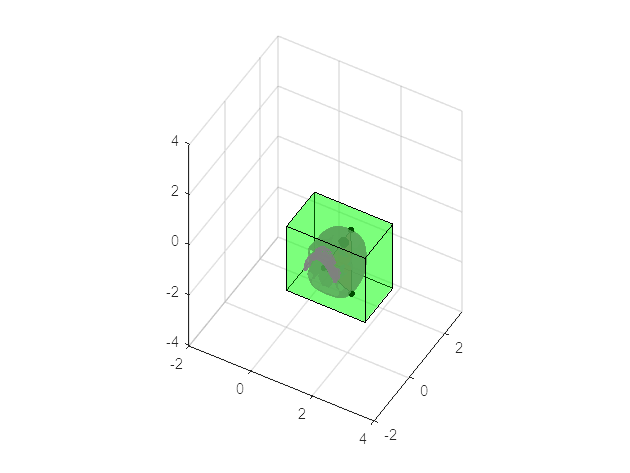


figure
hold on
surf(X*r+2.55-1.22,Y*r+1.568-0.252,Z*r-0.62,'FaceColor',[1 0 0])
surf(X*r+2.55-0.70,Y*r+1.568-1.12,Z*r-2.14,'FaceColor',[1 0 0])
surf(X*r+2.55-1.86,Y*r+1.568-0.658,Z*r-2.10,'FaceColor',[1 0 0])
surf(X*r2+2.55-1.32,Y*r2+1.568-0.49,Z*r2-0.97,'FaceColor',[1 0 0])
patch('Vertices', v_contenedor_0(1:3,:)', 'Faces', f, 'FaceVertexCData', hsv(6), 'FaceColor', [0 1 0], 'FaceAlpha', 0.3) 
patch('Vertices',v_craneo_0(1:3,:)','Faces',Skull.Fs,'FaceVertexCData',hsv(6),'FaceColor',[0.5 0.5 0.5], 'Edgecolor', 'none', 'FaceAlpha',0.8)
patch('Vertices',triangulo_fiducials,'Faces',caras_triangulo_fiducials,'FaceColor', [1 0 0], 'FaceAlpha', 0.3)
view(30, 45)
grid on
axis equal
axis([-2.0 4.0 -2.0 3.0 -4.0 4.0])

### Fiducials and Tumor wrt Human Reference Frame

Place fiducial and tumor in the head of the human. You will have to re-do the containing box secction.

**Expected results**

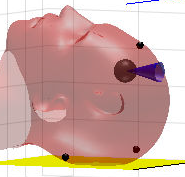

close all
% We translate what we have done before to our concrete case, using an
% smaller scale. In addition, we plot a cone in parallel with the zy plane
% of the table that goes from the center of the tumor to outside the skull
H = 0.255

H = 0.2550

W = 0.255

W = 0.2550

D = 0.1568

D = 0.1568

v_contenedor = [H 0 0; 0 W 0; 0 0 D]*v_cubo'

v_contenedor = 3×8
         0    0.2550    0.2550         0         0    0.2550    0.2550         0
         0         0    0.2550    0.2550         0         0    0.2550    0.2550
         0         0         0         0    0.1568    0.1568    0.1568    0.1568


v_contenedor(4,:) = 1

v_contenedor = 4×8
         0    0.2550    0.2550         0         0    0.2550    0.2550         0
         0         0    0.2550    0.2550         0         0    0.2550    0.2550
         0         0         0         0    0.1568    0.1568    0.1568    0.1568
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


T_contenedor_tabla = transl(2.25,0.3225,0.33)*trotz(pi/2)*trotx(-pi/2)

T_contenedor_tabla = 4×4
         0         0   -1.0000    2.2500
    1.0000         0         0    0.3225
         0   -1.0000         0    0.3300
         0         0         0    1.0000


T_contenedor_0 = T_tabla_0*T_contenedor_tabla

T_contenedor_0 = 4×4
   -0.8660         0   -0.5000    0.5457
    0.5000         0   -0.8660    1.6098
         0   -1.0000         0    1.1300
         0         0         0    1.0000


v_contenedor_0 = T_contenedor_0 * v_contenedor

v_contenedor_0 = 4×8
    0.5457    0.3249    0.3249    0.5457    0.4673    0.2465    0.2465    0.4673
    1.6098    1.7373    1.7373    1.6098    1.4740    1.6015    1.6015    1.4740
    1.1300    1.1300    0.8750    0.8750    1.1300    1.1300    0.8750    0.8750
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


T_fiducial1_contenedor = transl(0.07,0.214,0.112)

T_fiducial1_contenedor = 4×4
    1.0000         0         0    0.0700
         0    1.0000         0    0.2140
         0         0    1.0000    0.1120
         0         0         0    1.0000


T_fiducial1_0 = T_contenedor_0 * T_fiducial1_contenedor

T_fiducial1_0 = 4×4
   -0.8660         0   -0.5000    0.4291
    0.5000         0   -0.8660    1.5478
         0   -1.0000         0    0.9160
         0         0         0    1.0000


T_fiducial2_contenedor = transl(0.186,0.210,0.0658)

T_fiducial2_contenedor = 4×4
    1.0000         0         0    0.1860
         0    1.0000         0    0.2100
         0         0    1.0000    0.0658
         0         0         0    1.0000


T_fiducial2_0 = T_contenedor_0 * T_fiducial2_contenedor

T_fiducial2_0 = 4×4
   -0.8660         0   -0.5000    0.3517
    0.5000         0   -0.8660    1.6458
         0   -1.0000         0    0.9200
         0         0         0    1.0000


T_fiducial3_contenedor = transl(0.122,0.064,0.0252)

T_fiducial3_contenedor = 4×4
    1.0000         0         0    0.1220
         0    1.0000         0    0.0640
         0         0    1.0000    0.0252
         0         0         0    1.0000


T_fiducial3_0 = T_contenedor_0 * T_fiducial3_contenedor

T_fiducial3_0 = 4×4
   -0.8660         0   -0.5000    0.4275
    0.5000         0   -0.8660    1.6490
         0   -1.0000         0    1.0660
         0         0         0    1.0000


T_tumor_contenedor = transl(0.132,0.099,0.050)

T_tumor_contenedor = 4×4
    1.0000         0         0    0.1320
         0    1.0000         0    0.0990
         0         0    1.0000    0.0500
         0         0         0    1.0000


T_tumor_0 = T_contenedor_0 * T_tumor_contenedor

T_tumor_0 = 4×4
   -0.8660         0   -0.5000    0.4064
    0.5000         0   -0.8660    1.6325
         0   -1.0000         0    1.0310
         0         0         0    1.0000



Cono = load('F_V_Cone.mat')

Cono = struct with fields:
    fvc: [1×1 struct]


H = 0.01

H = 0.0100

W = 0.01

W = 0.0100

D = 0.0495

D = 0.0495

v_cono = [H 0 0; 0 W 0; 0 0 D]*Cono.fvc.vertices'

v_cono = 3×42
    0.0100         0    0.0095         0    0.0081         0    0.0059         0    0.0031         0    0.0000         0   -0.0031         0   -0.0059         0   -0.0081         0   -0.0095         0   -0.0100         0   -0.0095         0   -0.0081         0   -0.0059         0   -0.0031         0
         0         0    0.0031         0    0.0059         0    0.0081         0    0.0095         0    0.0100         0    0.0095         0    0.0081         0    0.0059         0    0.0031         0    0.0000         0   -0.0031         0   -0.0059         0   -0.0081         0   -0.0095         0
         0    0.0495         0    0.0495         0    0.0495         0    0.0495         0    0.0495         0    0.0495         0    0.0495         0    0.0495         0    0.0495         0    0.0495         0    0.0495         0    0.0495         0    0.0495         0    0.0495         0    0.0495


v_cono(4,:) = 1

v_cono = 4×42
    0.0100         0    0.0095         0    0.0081         0    0.0059         0    0.0031         0    0.0000         0   -0.0031         0   -0.0059         0   -0.0081         0   -0.0095         0   -0.0100         0   -0.0095         0   -0.0081         0   -0.0059         0   -0.0031         0
         0         0    0.0031         0    0.0059         0    0.0081         0    0.0095         0    0.0100         0    0.0095         0    0.0081         0    0.0059         0    0.0031         0    0.0000         0   -0.0031         0   -0.0059         0   -0.0081         0   -0.0095         0
         0    0.0495         0    0.0495         0    0.0495         0    0.0495         0    0.0495         0    0.0495         0    0.0495         0    0.0495         0    0.0495         0    0.0495         0    0.0495         0    0.0495         0    0.0495         0    0.0495         0    0.0495
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000   

T_cono_contenedor = transl(0.132,0.099,0.0)

T_cono_contenedor = 4×4
    1.0000         0         0    0.1320
         0    1.0000         0    0.0990
         0         0    1.0000         0
         0         0         0    1.0000


T_cono_0 = T_contenedor_0 * T_cono_contenedor

T_cono_0 = 4×4
   -0.8660         0   -0.5000    0.4314
    0.5000         0   -0.8660    1.6758
         0   -1.0000         0    1.0310
         0         0         0    1.0000


v_cono_0 = T_cono_0 * v_cono

v_cono_0 = 4×42
    0.4227    0.4066    0.4232    0.4066    0.4244    0.4066    0.4263    0.4066    0.4287    0.4066    0.4314    0.4066    0.4341    0.4066    0.4365    0.4066    0.4384    0.4066    0.4396    0.4066    0.4401    0.4066    0.4396    0.4066    0.4384    0.4066    0.4365    0.4066    0.4341    0.4066
    1.6808    1.6329    1.6806    1.6329    1.6799    1.6329    1.6787    1.6329    1.6774    1.6329    1.6758    1.6329    1.6743    1.6329    1.6729    1.6329    1.6718    1.6329    1.6711    1.6329    1.6708    1.6329    1.6711    1.6329    1.6718    1.6329    1.6729    1.6329    1.6743    1.6329
    1.0310    1.0310    1.0279    1.0310    1.0251    1.0310    1.0229    1.0310    1.0215    1.0310    1.0210    1.0310    1.0215    1.0310    1.0229    1.0310    1.0251    1.0310    1.0279    1.0310    1.0310    1.0310    1.0341    1.0310    1.0369    1.0310    1.0391    1.0310    1.0405    1.0310
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000 

r = 0.008

r = 0.0080

r2 = 0.0145

r2 = 0.0145

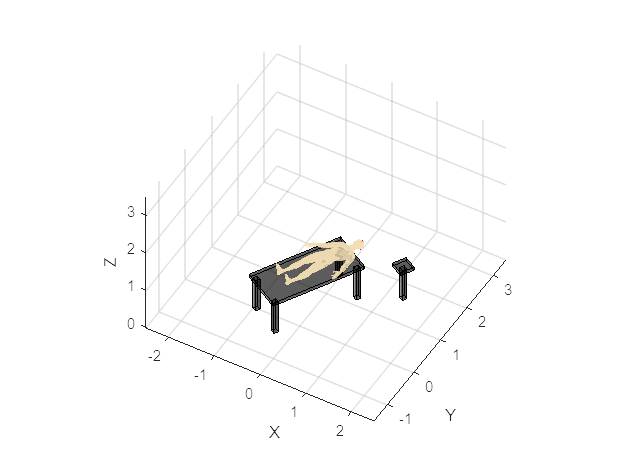


figure
hold on
patch('Vertices',v_tabla_0(1:3,:)','Faces',f,'FaceVertexCData',hsv(6),'FaceColor','black','FaceAlpha',0.4)
patch('Vertices',v_pata1_0(1:3,:)','Faces',f,'FaceVertexCData',hsv(6),'FaceColor','black','FaceAlpha',0.4)
patch('Vertices',v_pata2_0(1:3,:)','Faces',f,'FaceVertexCData',hsv(6),'FaceColor','black','FaceAlpha',0.4)
patch('Vertices',v_pata3_0(1:3,:)','Faces',f,'FaceVertexCData',hsv(6),'FaceColor','black','FaceAlpha',0.4)
patch('Vertices',v_pata4_0(1:3,:)','Faces',f,'FaceVertexCData',hsv(6),'FaceColor','black','FaceAlpha',0.4)
patch('Vertices',v_tablaherramientas_0(1:3,:)','Faces',f,'FaceVertexCData',hsv(6),'FaceColor','black','FaceAlpha',0.4)
patch('Vertices',v_pataherramientas_0(1:3,:)','Faces',f,'FaceVertexCData',hsv(6),'FaceColor','black','FaceAlpha',0.4)
patch('Vertices',v_cono_0(1:3,:)','Faces',Cono.fvc.faces,'FaceVertexCData',hsv(6),'FaceColor','b','FaceAlpha',0.3, 'EdgeColor','none')
patch('Vertices',v_humano_0(1:3,:)','Faces',Human.Fh,'FaceVertexCData',hsv(6),'FaceColor',[0.95,0.87,0.7], 'Edgecolor', 'none', 'FaceAlpha',0.8)
surf(X*r+T_fiducial1_0(1,4),Y*r+T_fiducial1_0(2,4),Z*r+T_fiducial1_0(3,4),'FaceColor',[1 0 0], 'EdgeColor','none')
surf(X*r+T_fiducial2_0(1,4),Y*r+T_fiducial2_0(2,4),Z*r+T_fiducial2_0(3,4),'FaceColor',[1 0 0], 'EdgeColor','none')
surf(X*r+T_fiducial3_0(1,4),Y*r+T_fiducial3_0(2,4),Z*r+T_fiducial3_0(3,4),'FaceColor',[1 0 0], 'EdgeColor','none')
surf(X*r2+T_tumor_0(1,4),Y*r2+T_tumor_0(2,4),Z*r2+T_tumor_0(3,4),'FaceColor',[1 0 0], 'EdgeColor','none')
view(30,45)
grid on
xyzlabel
axis equal
axis([-2.5 2.5 -1.5 3.5 0.0 3.5])

## *First approach (10%)  *

*Asume that the ZX plane of the Robot is aligned with the plane of symmetry of the human body.*

### Robot manipulator

Consider  the best position of manipulator to be nearby the operating table to warranty that the head is in the reachable work space. Use a Puma 560. Use p560.teach to play.

Use: p560.base & p560.tool to locate the Puma and add the tools.

**Expected results**

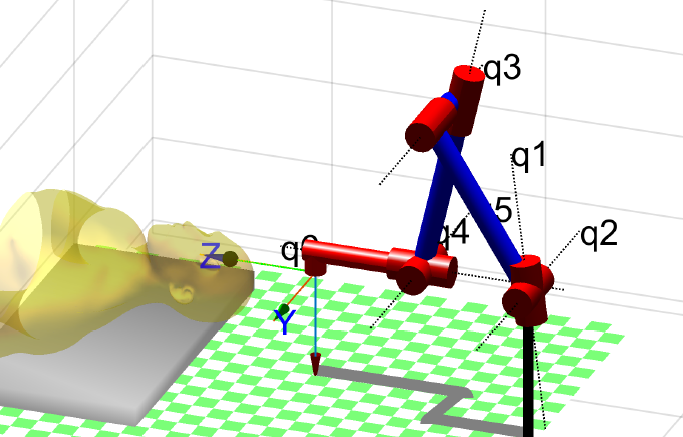

% Now we place a puma560 with respect to the table in a place that the head
% is reachable to do the surgery
mdl_puma560
% (l1-l2)^2 <= (x^2+y^2) <= (l1+l2)^2
T_p560_tabla = transl(3,0.45,0.08)*trotz(pi)

T_p560_tabla = 4×4
   -1.0000         0         0    3.0000
         0   -1.0000         0    0.4500
         0         0    1.0000    0.0800
         0         0         0    1.0000


T_p560_0 = T_tabla_0*T_p560_tabla

T_p560_0 = 4×4
   -0.5000    0.8660         0    0.8103
   -0.8660   -0.5000         0    2.3231
         0         0    1.0000    0.8800
         0         0         0    1.0000


p560.base = T_p560_0

 
p560 = 
 
Puma 560 [Unimation]:: 6 axis, RRRRRR, stdDH, slowRNE            
 - viscous friction; params of 8/95;                             
+---+-----------+-----------+-----------+-----------+-----------+
| j |     theta |         d |         a |     alpha |    offset |
+---+-----------+-----------+-----------+-----------+-----------+
|  1|         q1|          0|          0|     1.5708|          0|
|  2|         q2|          0|     0.4318|          0|          0|
|  3|         q3|    0.15005|     0.0203|    -1.5708|          0|
|  4|         q4|     0.4318|          0|     1.5708|          0|
|  5|         q5|          0|          0|    -1.5708|          0|
|  6|         q6|          0|          0|          0|          0|
+---+-----------+-----------+-----------+-----------+-----------+
base:    t = (0.81, 2.32, 0.88), RPY/xyz = (-120, 0, 0) deg      
 


p560.tool=transl(0.05,0,0.2)

 
p560 = 
 
Puma 560 [Unimation]:: 6 axis, RRRRRR, stdDH, slowRNE            
 - viscous friction; params of 8/95;                             
+---+-----------+-----------+-----------+-----------+-----------+
| j |     theta |         d |         a |     alpha |    offset |
+---+-----------+-----------+-----------+-----------+-----------+
|  1|         q1|          0|          0|     1.5708|          0|
|  2|         q2|          0|     0.4318|          0|          0|
|  3|         q3|    0.15005|     0.0203|    -1.5708|          0|
|  4|         q4|     0.4318|          0|     1.5708|          0|
|  5|         q5|          0|          0|    -1.5708|          0|
|  6|         q6|          0|          0|          0|          0|
+---+-----------+-----------+-----------+-----------+-----------+
base:    t = (0.81, 2.32, 0.88), RPY/xyz = (-120, 0, 0) deg      
tool:    t = (0.05, 0, 0.2), RPY/xyz = (0, 0, 0) deg             
 


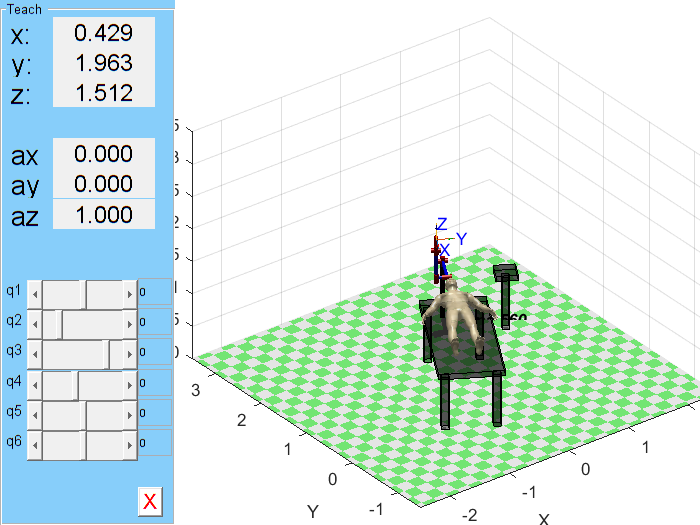

p560.plot(qr, 'workspace', [-2.5 2.5 -1.5 3.5 0.0 3.5], 'scale', 0.5);
p560.teach('approach')

### Reference Frames

Display all necessary reference frame. Use best scale to see it.

- {U} Univers [0 0 0]

- {R} Robot

- {I} Image

- {Tb} Table_body

- {Tt} Table tool

- {EE} End Efector

- others

- ...

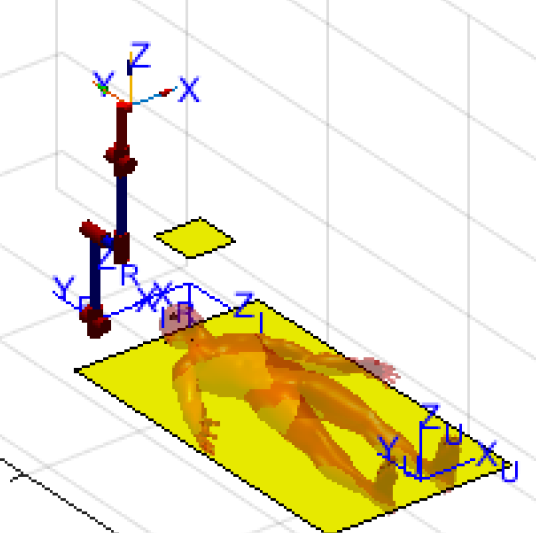

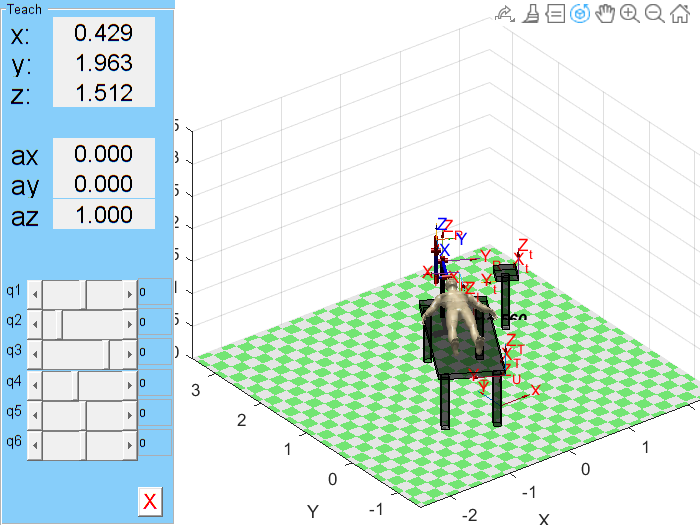

trplot(T_contenedor_0,'frame','I' ,'color', 'r','arrow','width',0.4,'length',0.5)
trplot(transl(0,0,0),'frame','U','color','r','arrow','width',0.4,'length',0.5)
trplot(T_p560_0,'frame', 'R', 'color', 'r','arrow','width',0.4,'length',0.5)
trplot(T_tabla_0,'frame', 'T', 'color', 'r', 'arrow','width',0.4,'length',0.5)
trplot(T_tablaherramientas_0,'frame','t','color','r','arrow','width',0.4,'length',0.5)

## Surgery (55%)

### Biospy

Prepare a script that perform a biopsy. Zoom in the scene and record a video with the best view.

Use a tool that has the following Transformation: transl(0.05 0 0.25)

Let us see the 'trail' option of plot to visualize the trajectory.

close all

figure
hold on
patch('Vertices',v_tabla_0(1:3,:)','Faces',f,'FaceVertexCData',hsv(6),'FaceColor','black','FaceAlpha',0.4)
patch('Vertices',v_pata1_0(1:3,:)','Faces',f,'FaceVertexCData',hsv(6),'FaceColor','black','FaceAlpha',0.4)
patch('Vertices',v_pata2_0(1:3,:)','Faces',f,'FaceVertexCData',hsv(6),'FaceColor','black','FaceAlpha',0.4)
patch('Vertices',v_pata3_0(1:3,:)','Faces',f,'FaceVertexCData',hsv(6),'FaceColor','black','FaceAlpha',0.4)
patch('Vertices',v_pata4_0(1:3,:)','Faces',f,'FaceVertexCData',hsv(6),'FaceColor','black','FaceAlpha',0.4)
patch('Vertices',v_tablaherramientas_0(1:3,:)','Faces',f,'FaceVertexCData',hsv(6),'FaceColor','black','FaceAlpha',0.4)
patch('Vertices',v_pataherramientas_0(1:3,:)','Faces',f,'FaceVertexCData',hsv(6),'FaceColor','black','FaceAlpha',0.4)
patch('Vertices',v_humano_0(1:3,:)','Faces',Human.Fh,'FaceVertexCData',hsv(6),'FaceColor',[0.95,0.87,0.7], 'Edgecolor', 'none', 'FaceAlpha',0.8)
surf(X*r+T_fiducial1_0(1,4),Y*r+T_fiducial1_0(2,4),Z*r+T_fiducial1_0(3,4),'FaceColor',[1 0 0], 'EdgeColor','none')
surf(X*r+T_fiducial2_0(1,4),Y*r+T_fiducial2_0(2,4),Z*r+T_fiducial2_0(3,4),'FaceColor',[1 0 0], 'EdgeColor','none')
surf(X*r+T_fiducial3_0(1,4),Y*r+T_fiducial3_0(2,4),Z*r+T_fiducial3_0(3,4),'FaceColor',[1 0 0], 'EdgeColor','none')
surf(X*r2+T_tumor_0(1,4),Y*r2+T_tumor_0(2,4),Z*r2+T_tumor_0(3,4),'FaceColor',[1 0 0], 'EdgeColor','none')
view(30,45)
grid on
xyzlabel
axis equal
axis([-2.5 2.5 -1.5 3.5 0.0 3.5])

% We set the appropriate tool to do the biopsy and then we set the frames
% that will divide our trajectories
p560.tool = transl(0.05,0,0.25)

 
p560 = 
 
Puma 560 [Unimation]:: 6 axis, RRRRRR, stdDH, slowRNE            
 - viscous friction; params of 8/95;                             
+---+-----------+-----------+-----------+-----------+-----------+
| j |     theta |         d |         a |     alpha |    offset |
+---+-----------+-----------+-----------+-----------+-----------+
|  1|         q1|          0|          0|     1.5708|          0|
|  2|         q2|          0|     0.4318|          0|          0|
|  3|         q3|    0.15005|     0.0203|    -1.5708|          0|
|  4|         q4|     0.4318|          0|     1.5708|          0|
|  5|         q5|          0|          0|    -1.5708|          0|
|  6|         q6|          0|          0|          0|          0|
+---+-----------+-----------+-----------+-----------+-----------+
base:    t = (0.81, 2.32, 0.88), RPY/xyz = (-120, 0, 0) deg      
tool:    t = (0.05, 0, 0.25), RPY/xyz = (0, 0, 0) deg            
 


T1 = T_contenedor_0*(T_tumor_contenedor*transl(0.0,0.0,-0.3)*trotz(pi/2)) % From robot initial pose to a distance = 0.3 from tumor

T1 = 4×4
         0    0.8660   -0.5000    0.5564
         0   -0.5000   -0.8660    1.8923
   -1.0000         0         0    1.0310
         0         0         0    1.0000


T2 = T_contenedor_0*(T_tumor_contenedor*trotz(pi/2)) % From T1 final point to tumor

T2 = 4×4
         0    0.8660   -0.5000    0.4064
         0   -0.5000   -0.8660    1.6325
   -1.0000         0         0    1.0310
         0         0         0    1.0000


T0 = p560.fkine(qr)

 

T0 = 
   -0.5000    0.8660         0    0.6452
   -0.8660   -0.5000         0     2.337
         0         0         1     1.994
         0         0         0         1


q_0 = p560.ikine6s(T0,'run');
q_1 = p560.ikine6s(T1,'run');
t_0 = linspace(0.0,3.0,30)

t_0 = 1×30
         0    0.1034    0.2069    0.3103    0.4138    0.5172    0.6207    0.7241    0.8276    0.9310    1.0345    1.1379    1.2414    1.3448    1.4483    1.5517    1.6552    1.7586    1.8621    1.9655    2.0690    2.1724    2.2759    2.3793    2.4828    2.5862    2.6897    2.7931    2.8966    3.0000


Q_0 = jtraj(q_0,q_1,t_0); % For the first trajectory we follow an eliptic path
t_1 = linspace(0.0,5.0,50);
S = tpoly(0,1,t_1);
S(1) = 0

S = 50×1
         0
    0.0001
    0.0006
    0.0021
    0.0048
    0.0091
    0.0152
    0.0233
    0.0336
    0.0461


S(50) = 1

S = 50×1
         0
    0.0001
    0.0006
    0.0021
    0.0048
    0.0091
    0.0152
    0.0233
    0.0336
    0.0461


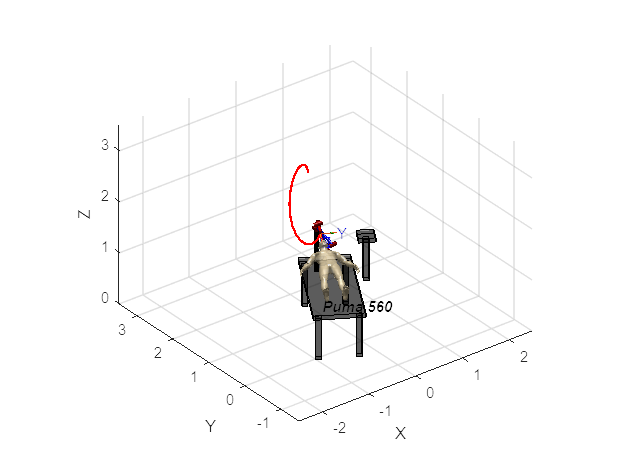

T_1_2 = ctraj(T1,T2,S); % For the second trajectory we follow an straight path with non constant velocity
Q_1 = p560.ikine(T_1_2);
T_2_1 = ctraj(T2,T1,S); % We will perform a third trajectory that consists in returning to T1
Q_2 = p560.ikine(T_2_1);
QT = [Q_0;Q_1;Q_2];
p560.plot(QT,'zoom',2,'trail',{'r', 'LineWidth', 1.5});

### Trepanation

Prepare a script that perform trepanation. Zoom in the scene and record a video with the best view.

Use a tool that has the following Transformation: transl(0 0 0.2)

Let us see the 'trail' option of plot to visualize the trajectory. Place a 45º cone on top of the trepanation to better understand. See: 6_Plot_Box_Cone.mlx. You will have to scale it. Play with transparency.

close all

% We plot a cone in top of the skull forming 45 degrees with its
% longitudinal axis 
Cono = load('F_V_Cone.mat')

Cono = struct with fields:
    fvc: [1×1 struct]


H = 0.2

H = 0.2000

W = 0.2

W = 0.2000

D = 0.2

D = 0.2000

v_cono = [H 0 0; 0 W 0; 0 0 D]*Cono.fvc.vertices'

v_cono = 3×42
    0.2000         0    0.1902         0    0.1618         0    0.1176         0    0.0618         0    0.0000         0   -0.0618         0   -0.1176         0   -0.1618         0   -0.1902         0   -0.2000         0   -0.1902         0   -0.1618         0   -0.1176         0   -0.0618         0
         0         0    0.0618         0    0.1176         0    0.1618         0    0.1902         0    0.2000         0    0.1902         0    0.1618         0    0.1176         0    0.0618         0    0.0000         0   -0.0618         0   -0.1176         0   -0.1618         0   -0.1902         0
         0    0.2000         0    0.2000         0    0.2000         0    0.2000         0    0.2000         0    0.2000         0    0.2000         0    0.2000         0    0.2000         0    0.2000         0    0.2000         0    0.2000         0    0.2000         0    0.2000         0    0.2000


v_cono(4,:) = 1

v_cono = 4×42
    0.2000         0    0.1902         0    0.1618         0    0.1176         0    0.0618         0    0.0000         0   -0.0618         0   -0.1176         0   -0.1618         0   -0.1902         0   -0.2000         0   -0.1902         0   -0.1618         0   -0.1176         0   -0.0618         0
         0         0    0.0618         0    0.1176         0    0.1618         0    0.1902         0    0.2000         0    0.1902         0    0.1618         0    0.1176         0    0.0618         0    0.0000         0   -0.0618         0   -0.1176         0   -0.1618         0   -0.1902         0
         0    0.2000         0    0.2000         0    0.2000         0    0.2000         0    0.2000         0    0.2000         0    0.2000         0    0.2000         0    0.2000         0    0.2000         0    0.2000         0    0.2000         0    0.2000         0    0.2000         0    0.2000
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000   

T_cono_contenedor = transl(0.132,0.099,-0.2)

T_cono_contenedor = 4×4
    1.0000         0         0    0.1320
         0    1.0000         0    0.0990
         0         0    1.0000   -0.2000
         0         0         0    1.0000


T_cono_0 = T_contenedor_0 * T_cono_contenedor

T_cono_0 = 4×4
   -0.8660         0   -0.5000    0.5314
    0.5000         0   -0.8660    1.8490
         0   -1.0000         0    1.0310
         0         0         0    1.0000


v_cono_0 = T_cono_0 * v_cono

v_cono_0 = 4×42
    0.3582    0.4314    0.3667    0.4314    0.3913    0.4314    0.4296    0.4314    0.4779    0.4314    0.5314    0.4314    0.5849    0.4314    0.6332    0.4314    0.6715    0.4314    0.6961    0.4314    0.7046    0.4314    0.6961    0.4314    0.6715    0.4314    0.6332    0.4314    0.5849    0.4314
    1.9490    1.6758    1.9441    1.6758    1.9299    1.6758    1.9078    1.6758    1.8799    1.6758    1.8490    1.6758    1.8181    1.6758    1.7902    1.6758    1.7681    1.6758    1.7539    1.6758    1.7490    1.6758    1.7539    1.6758    1.7681    1.6758    1.7902    1.6758    1.8181    1.6758
    1.0310    1.0310    0.9692    1.0310    0.9134    1.0310    0.8692    1.0310    0.8408    1.0310    0.8310    1.0310    0.8408    1.0310    0.8692    1.0310    0.9134    1.0310    0.9692    1.0310    1.0310    1.0310    1.0928    1.0310    1.1486    1.0310    1.1928    1.0310    1.2212    1.0310
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000 


figure
hold on
patch('Vertices',v_tabla_0(1:3,:)','Faces',f,'FaceVertexCData',hsv(6),'FaceColor','black','FaceAlpha',0.4)
patch('Vertices',v_pata1_0(1:3,:)','Faces',f,'FaceVertexCData',hsv(6),'FaceColor','black','FaceAlpha',0.4)
patch('Vertices',v_pata2_0(1:3,:)','Faces',f,'FaceVertexCData',hsv(6),'FaceColor','black','FaceAlpha',0.4)
patch('Vertices',v_pata3_0(1:3,:)','Faces',f,'FaceVertexCData',hsv(6),'FaceColor','black','FaceAlpha',0.4)
patch('Vertices',v_pata4_0(1:3,:)','Faces',f,'FaceVertexCData',hsv(6),'FaceColor','black','FaceAlpha',0.4)
patch('Vertices',v_cono_0(1:3,:)','Faces',Cono.fvc.faces,'FaceVertexCData',hsv(6),'FaceColor','b','FaceAlpha',0.2, 'EdgeColor','none')
patch('Vertices',v_tablaherramientas_0(1:3,:)','Faces',f,'FaceVertexCData',hsv(6),'FaceColor','black','FaceAlpha',0.4)
patch('Vertices',v_pataherramientas_0(1:3,:)','Faces',f,'FaceVertexCData',hsv(6),'FaceColor','black','FaceAlpha',0.4)
patch('Vertices',v_humano_0(1:3,:)','Faces',Human.Fh,'FaceVertexCData',hsv(6),'FaceColor',[0.95,0.87,0.7], 'Edgecolor', 'none', 'FaceAlpha',0.8)
surf(X*r+T_fiducial1_0(1,4),Y*r+T_fiducial1_0(2,4),Z*r+T_fiducial1_0(3,4),'FaceColor',[1 0 0], 'EdgeColor','none')
surf(X*r+T_fiducial2_0(1,4),Y*r+T_fiducial2_0(2,4),Z*r+T_fiducial2_0(3,4),'FaceColor',[1 0 0], 'EdgeColor','none')
surf(X*r+T_fiducial3_0(1,4),Y*r+T_fiducial3_0(2,4),Z*r+T_fiducial3_0(3,4),'FaceColor',[1 0 0], 'EdgeColor','none')
surf(X*r2+T_tumor_0(1,4),Y*r2+T_tumor_0(2,4),Z*r2+T_tumor_0(3,4),'FaceColor',[1 0 0], 'EdgeColor','none')
view(30,45)
grid on
xyzlabel
axis equal
axis([-2.5 2.5 -1.5 3.5 0.0 3.5])

% We set the appropriate tool to do the trepanation and then we set the frames
% that will divide our trajectories
p560.tool = transl(0.0,0,0.2)

 
p560 = 
 
Puma 560 [Unimation]:: 6 axis, RRRRRR, stdDH, slowRNE            
 - viscous friction; params of 8/95;                             
+---+-----------+-----------+-----------+-----------+-----------+
| j |     theta |         d |         a |     alpha |    offset |
+---+-----------+-----------+-----------+-----------+-----------+
|  1|         q1|          0|          0|     1.5708|          0|
|  2|         q2|          0|     0.4318|          0|          0|
|  3|         q3|    0.15005|     0.0203|    -1.5708|          0|
|  4|         q4|     0.4318|          0|     1.5708|          0|
|  5|         q5|          0|          0|    -1.5708|          0|
|  6|         q6|          0|          0|          0|          0|
+---+-----------+-----------+-----------+-----------+-----------+
base:    t = (0.81, 2.32, 0.88), RPY/xyz = (-120, 0, 0) deg      
tool:    t = (0, 0, 0.2), RPY/xyz = (0, 0, 0) deg                
 


T1 = T_contenedor_0*(T_tumor_contenedor*transl(0.0,-0.00725,-0.05)*trotz(pi/2)*troty(pi/4)) % From robot initial pose to first trepanation point

T1 = 4×4
    0.3536    0.8660   -0.3536    0.4314
    0.6124   -0.5000   -0.6124    1.6758
   -0.7071         0   -0.7071    1.0383
         0         0         0    1.0000


T0 = p560.fkine(qr)

 

T0 = 
   -0.5000    0.8660         0    0.6702
   -0.8660   -0.5000         0     2.381
         0         0         1     1.944
         0         0         0         1


q_0 = p560.ikine6s(T0,'run');
q_1 = p560.ikine6s(T1,'run');
t_0 = linspace(0.0,3.0,30)

t_0 = 1×30
         0    0.1034    0.2069    0.3103    0.4138    0.5172    0.6207    0.7241    0.8276    0.9310    1.0345    1.1379    1.2414    1.3448    1.4483    1.5517    1.6552    1.7586    1.8621    1.9655    2.0690    2.1724    2.2759    2.3793    2.4828    2.5862    2.6897    2.7931    2.8966    3.0000


% We do the trepanation always perforing the skull with 45 degrees wrt the
% longitudinal axis of the human
for i=1:50
Trepanation_Pose(:,:,i)= T_contenedor_0*(T_tumor_contenedor*transl(0.0,0.0,-0.05)*trotz((2*pi*i/50)+pi/2)*transl(0.0,-0.00725,0)*troty(pi/4));
end
Q_0 = jtraj(q_0,q_1,t_0); % For the first trajectory we follow an eliptic path
Q_1 = p560.ikine6s(Trepanation_Pose, 'run'); % For the trepanation we follow constant velocity
Q_2 = jtraj(q_1,q_0,t_0) % We return to initial position

Q_2 = 30×6
    0.2417    1.1693   -2.9213    2.8538    0.6389   -2.7357
    0.2416    1.1695   -2.9208    2.8539    0.6387   -2.7334
    0.2410    1.1705   -2.9174    2.8546    0.6370   -2.7183
    0.2394    1.1731   -2.9086    2.8565    0.6329   -2.6803
    0.2366    1.1778   -2.8928    2.8599    0.6254   -2.6116
    0.2323    1.1849   -2.8688    2.8650    0.6140   -2.5070
    0.2264    1.1948   -2.8358    2.8720    0.5984   -2.3633
    0.2189    1.2073   -2.7935    2.8810    0.5784   -2.1795
    0.2097    1.2226   -2.7422    2.8920    0.5542   -1.9561
    0.1989    1.2404   -2.6823    2.9047    0.5258   -1.6952


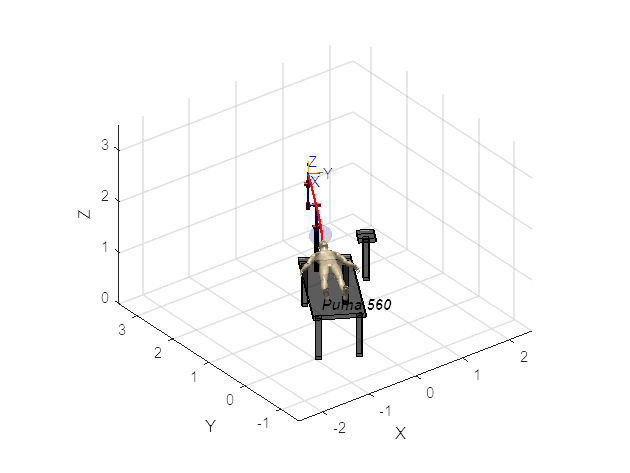

QT = [Q_0;Q_1;Q_2];
p560.plot(QT,'zoom',2,'trail',{'r', 'LineWidth', 1.5});

### Tumor burning

Prepare a script that perform tumor burning with the laser.  Zoom in the scene and record a video with the best view.

You ought to think in an algorithm, that in order, fill up the tumor's  equivalent sphere with small burning spheres of 4m diameter.

Use a tool that has the following Transformation: transl(0 0 0.2)

close all

figure
hold on

% We plot the tumor subdivided in little spheres with radius = 4mm
esferas = zeros(33, 3)

esferas = 33×3
     0     0     0
     0     0     0
     0     0     0
     0     0     0
     0     0     0
     0     0     0
     0     0     0
     0     0     0
     0     0     0
     0     0     0


i = 1

i = 1

rpeq = 0.004;
rgran = 0.0145;
[x, y, z] = sphere;
w = linspace(-rgran + rpeq, rgran - rpeq, 4);
light('Position',[2 3 1])

for ix = w
   for iy = w
      for iz = w
          if (ix)^2 + (iy)^2 + (iz)^2 < rgran^2

              esferas(i,:) = [ix iy iz];
              surf(x * rpeq + ix + T_tumor_0(1,4), y * rpeq + iy + T_tumor_0(2,4), z * rpeq + iz + T_tumor_0(3,4),...
                  'FaceColor',[1 0 0], 'EdgeColor','none', 'FaceLighting', 'gouraud');
              i = i + 1

          end
      end
   end
end

i = 2

i = 3

i = 4

i = 5

i = 6

i = 7

i = 8

i = 9

i = 10

i = 11

i = 12

i = 13

i = 14

i = 15

i = 16

i = 17

i = 18

i = 19

i = 20

i = 21

i = 22

i = 23

i = 24

i = 25

i = 26

i = 27

i = 28

i = 29

i = 30

i = 31

i = 32

i = 33


patch('Vertices',v_tabla_0(1:3,:)','Faces',f,'FaceVertexCData',hsv(6),'FaceColor','black','FaceAlpha',0.4)
patch('Vertices',v_pata1_0(1:3,:)','Faces',f,'FaceVertexCData',hsv(6),'FaceColor','black','FaceAlpha',0.4)
patch('Vertices',v_pata2_0(1:3,:)','Faces',f,'FaceVertexCData',hsv(6),'FaceColor','black','FaceAlpha',0.4)
patch('Vertices',v_pata3_0(1:3,:)','Faces',f,'FaceVertexCData',hsv(6),'FaceColor','black','FaceAlpha',0.4)
patch('Vertices',v_pata4_0(1:3,:)','Faces',f,'FaceVertexCData',hsv(6),'FaceColor','black','FaceAlpha',0.4)
patch('Vertices',v_tablaherramientas_0(1:3,:)','Faces',f,'FaceVertexCData',hsv(6),'FaceColor','black','FaceAlpha',0.4)
patch('Vertices',v_pataherramientas_0(1:3,:)','Faces',f,'FaceVertexCData',hsv(6),'FaceColor','black','FaceAlpha',0.4)
patch('Vertices',v_humano_0(1:3,:)','Faces',Human.Fh,'FaceVertexCData',hsv(6),'FaceColor',[0.95,0.87,0.7], 'Edgecolor', 'none', 'FaceAlpha',0.4)
surf(X*r+T_fiducial1_0(1,4),Y*r+T_fiducial1_0(2,4),Z*r+T_fiducial1_0(3,4),'FaceColor',[1 0 0], 'EdgeColor','none')
surf(X*r+T_fiducial2_0(1,4),Y*r+T_fiducial2_0(2,4),Z*r+T_fiducial2_0(3,4),'FaceColor',[1 0 0], 'EdgeColor','none')
surf(X*r+T_fiducial3_0(1,4),Y*r+T_fiducial3_0(2,4),Z*r+T_fiducial3_0(3,4),'FaceColor',[1 0 0], 'EdgeColor','none')
view(30,45)
grid on
xyzlabel
axis equal
axis([-2.5 2.5 -1.5 3.5 0.0 3.5])

% We set the appropriate tool to do the burning and then we set the frames
% that will divide our trajectories
p560.tool = transl(0.0,0,0.2)

 
p560 = 
 
Puma 560 [Unimation]:: 6 axis, RRRRRR, stdDH, slowRNE            
 - viscous friction; params of 8/95;                             
+---+-----------+-----------+-----------+-----------+-----------+
| j |     theta |         d |         a |     alpha |    offset |
+---+-----------+-----------+-----------+-----------+-----------+
|  1|         q1|          0|          0|     1.5708|          0|
|  2|         q2|          0|     0.4318|          0|          0|
|  3|         q3|    0.15005|     0.0203|    -1.5708|          0|
|  4|         q4|     0.4318|          0|     1.5708|          0|
|  5|         q5|          0|          0|    -1.5708|          0|
|  6|         q6|          0|          0|          0|          0|
+---+-----------+-----------+-----------+-----------+-----------+
base:    t = (0.81, 2.32, 0.88), RPY/xyz = (-120, 0, 0) deg      
tool:    t = (0, 0, 0.2), RPY/xyz = (0, 0, 0) deg                
 


T1 = T_contenedor_0*(T_tumor_contenedor*transl(0.0,0.0,-0.3)*trotz(pi/2)) % From robot initial pose to first trepanation point

T1 = 4×4
         0    0.8660   -0.5000    0.5564
         0   -0.5000   -0.8660    1.8923
   -1.0000         0         0    1.0310
         0         0         0    1.0000


T0 = p560.fkine(qr)

 

T0 = 
   -0.5000    0.8660         0    0.6702
   -0.8660   -0.5000         0     2.381
         0         0         1     1.944
         0         0         0         1


q_0 = p560.ikine6s(T0,'run');
q_1 = p560.ikine6s(T1,'run');
t_0 = linspace(0.0,3.0,30)

t_0 = 1×30
         0    0.1034    0.2069    0.3103    0.4138    0.5172    0.6207    0.7241    0.8276    0.9310    1.0345    1.1379    1.2414    1.3448    1.4483    1.5517    1.6552    1.7586    1.8621    1.9655    2.0690    2.1724    2.2759    2.3793    2.4828    2.5862    2.6897    2.7931    2.8966    3.0000


Q_0 = jtraj(q_0,q_1,t_0); % For the first trajectory we follow an eliptic path

T_ini = T_contenedor_0*(T_tumor_contenedor*transl(0.0,0.0,-0.075)*trotz(pi/2))

T_ini = 4×4
         0    0.8660   -0.5000    0.4439
         0   -0.5000   -0.8660    1.6975
   -1.0000         0         0    1.0310
         0         0         0    1.0000


t_1 = linspace(0.0,5.0,50);
S = tpoly(0,1,t_1);
S(1) = 0

S = 50×1
         0
    0.0001
    0.0006
    0.0021
    0.0048
    0.0091
    0.0152
    0.0233
    0.0336
    0.0461


S(50) = 1

S = 50×1
         0
    0.0001
    0.0006
    0.0021
    0.0048
    0.0091
    0.0152
    0.0233
    0.0336
    0.0461


T_1_ini = ctraj(T1,T_ini,S); % For the second trajectory we follow an straight path with non constant velocity
Q_1 = p560.ikine(T_1_ini);
p560.plot([Q_0;Q_1],'zoom',2,'trail',{'r', 'LineWidth', 1.5});

q_ini = p560.ikine6s(T_ini)

q_ini = 1×6
    2.8432    1.9319    0.3109    2.6827    0.7258    0.3540


t_2 = linspace(0.0,0.5,5);

% Between each point to burn we create a trajectory, so we point one sphere
% and then we move the tool rotating it to point another
for i=1:33
    
    dy = sqrt((0.0-esferas(i,1))^2 + (-0.075-esferas(i,2))^2)
    dx = sqrt((0.0-esferas(i,3))^2 + (-0.075-esferas(i,2))^2)
    ax = asin(esferas(i,1)/dy)
    ay = asin(esferas(i,3)/dx)
    T_i = T_contenedor_0*(T_tumor_contenedor*transl(0.0,0.0,-0.075)*trotz(pi/2)*trotx(-ax)*troty(-ay));
    q_i = p560.ikine6s(T_i, 'lun');
    Q_i = jtraj(q_ini,q_i,t_2);
    p560.plot(Q_i,'zoom',2,'trail',{'r', 'LineWidth', 1.5});
    surf(x * rpeq + esferas(i,1) + T_tumor_0(1,4), y * rpeq + esferas(i,2) + T_tumor_0(2,4), z * rpeq + esferas(i,3) + T_tumor_0(3,4),...
                  'FaceColor','#006400', 'EdgeColor','none', 'FaceLighting', 'gouraud');
    q_ini = q_i
end

dy = 0.0723

dx = 0.0716

ax = -0.1458

ay = -0.0489

q_ini = 1×6
    2.8999    1.9244    0.2940    2.9726    0.6052    0.1347


dy = 0.0723

dx = 0.0716

ax = -0.1458

ay = 0.0489

q_ini = 1×6
    2.8999    1.9517    0.3103    3.0001    0.7454    0.1090


dy = 0.0792

dx = 0.0786

ax = -0.1330

ay = -0.0446

q_ini = 1×6
    2.8948    1.9246    0.2962    2.9435    0.6144    0.1575


dy = 0.0792

dx = 0.0786

ax = -0.1330

ay = 0.0446

q_ini = 1×6
    2.8948    1.9494    0.3111    2.9729    0.7417    0.1300


dy = 0.0646

dx = 0.0646

ax = -0.0542

ay = -0.0542

q_ini = 1×6
    2.8641    1.9183    0.2997    2.7555    0.6275    0.3056


dy = 0.0646

dx = 0.0646

ax = -0.0542

ay = 0.0542

q_ini = 1×6
    2.8641    1.9486    0.3179    2.8209    0.7774    0.2447


dy = 0.0716

dx = 0.0723

ax = -0.0489

ay = -0.1458

q_ini = 1×6
    2.8629    1.8981    0.2774    2.6572    0.5051    0.3976


dy = 0.0716

dx = 0.0716

ax = -0.0489

ay = -0.0489

q_ini = 1×6
    2.8621    1.9194    0.3010    2.7476    0.6371    0.3110


dy = 0.0716

dx = 0.0716

ax = -0.0489

ay = 0.0489

q_ini = 1×6
    2.8621    1.9469    0.3174    2.8081    0.7720    0.2548


dy = 0.0716

dx = 0.0723

ax = -0.0489

ay = 0.1458

q_ini = 1×6
    2.8629    1.9793    0.3260    2.8510    0.9051    0.2166


dy = 0.0786

dx = 0.0792

ax = -0.0446

ay = -0.1330

q_ini = 1×6
    2.8611    1.9005    0.2811    2.6607    0.5247    0.3923


dy = 0.0786

dx = 0.0786

ax = -0.0446

ay = -0.0446

q_ini = 1×6
    2.8604    1.9204    0.3021    2.7413    0.6449    0.3153


dy = 0.0786

dx = 0.0786

ax = -0.0446

ay = 0.0446

q_ini = 1×6
    2.8604    1.9454    0.3170    2.7975    0.7676    0.2631


dy = 0.0786

dx = 0.0792

ax = -0.0446

ay = 0.1330

q_ini = 1×6
    2.8611    1.9746    0.3255    2.8385    0.8889    0.2265


dy = 0.0856

dx = 0.0856

ax = -0.0409

ay = -0.0409

q_ini = 1×6
    2.8589    1.9213    0.3029    2.7361    0.6515    0.3188


dy = 0.0856

dx = 0.0856

ax = -0.0409

ay = 0.0409

q_ini = 1×6
    2.8589    1.9442    0.3166    2.7885    0.7639    0.2702


dy = 0.0646

dx = 0.0646

ax = 0.0542

ay = -0.0542

q_ini = 1×6
    2.8231    1.9186    0.2992    2.5290    0.6846    0.4774


dy = 0.0646

dx = 0.0646

ax = 0.0542

ay = 0.0542

q_ini = 1×6
    2.8231    1.9490    0.3173    2.6232    0.8241    0.3908


dy = 0.0716

dx = 0.0723

ax = 0.0489

ay = -0.1458

q_ini = 1×6
    2.8263    1.8985    0.2770    2.4267    0.5676    0.5765


dy = 0.0716

dx = 0.0716

ax = 0.0489

ay = -0.0489

q_ini = 1×6
    2.8250    1.9198    0.3005    2.5446    0.6881    0.4648


dy = 0.0716

dx = 0.0716

ax = 0.0489

ay = 0.0489

q_ini = 1×6
    2.8250    1.9472    0.3169    2.6286    0.8145    0.3876


dy = 0.0716

dx = 0.0723

ax = 0.0489

ay = 0.1458

q_ini = 1×6
    2.8263    1.9796    0.3255    2.6904    0.9411    0.3333


dy = 0.0786

dx = 0.0792

ax = 0.0446

ay = -0.1330

q_ini = 1×6
    2.8277    1.9008    0.2807    2.4542    0.5801    0.5521


dy = 0.0786

dx = 0.0786

ax = 0.0446

ay = -0.0446

q_ini = 1×6
    2.8266    1.9208    0.3016    2.5574    0.6911    0.4545


dy = 0.0786

dx = 0.0786

ax = 0.0446

ay = 0.0446

q_ini = 1×6
    2.8266    1.9457    0.3165    2.6330    0.8067    0.3849


dy = 0.0786

dx = 0.0792

ax = 0.0446

ay = 0.1330

q_ini = 1×6
    2.8277    1.9749    0.3250    2.6901    0.9225    0.3345


dy = 0.0856

dx = 0.0856

ax = 0.0409

ay = -0.0409

q_ini = 1×6
    2.8279    1.9216    0.3025    2.5680    0.6936    0.4459


dy = 0.0856

dx = 0.0856

ax = 0.0409

ay = 0.0409

q_ini = 1×6
    2.8279    1.9445    0.3162    2.6368    0.8001    0.3826


dy = 0.0723

dx = 0.0716

ax = 0.1458

ay = -0.0489

q_ini = 1×6
    2.7902    1.9254    0.2925    2.3705    0.7527    0.5903


dy = 0.0723

dx = 0.0716

ax = 0.1458

ay = 0.0489

q_ini = 1×6
    2.7902    1.9527    0.3089    2.4681    0.8692    0.5022


dy = 0.0792

dx = 0.0786

ax = 0.1330

ay = -0.0446

q_ini = 1×6
    2.7946    1.9255    0.2949    2.3970    0.7487    0.5707


dy = 0.0792

dx = 0.0786

ax = 0.1330

ay = 0.0446

q_ini = 1×6
    2.7946    1.9503    0.3098    2.4846    0.8560    0.4913


dy = 0.0750

dx = 0.0750

ax = 0

ay = 0

q_ini = 1×6
    2.8432    1.9319    0.3109    2.6827    0.7258    0.3540


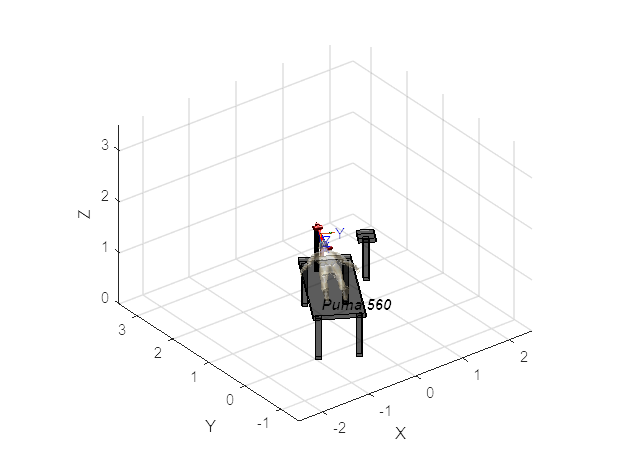


T_ini_1 = ctraj(T_ini, T1, S); % Finally we return to T1 with a cartesian trajectory
Q_2 = p560.ikine(T_ini_1);
p560.plot(Q_2,'zoom',2,'trail',{'r', 'LineWidth', 1.5});

## *Second approach: ( 25%)*

Modify your code  to repeat the exercise if  the table with the patient is given as happend in the Rosa video.

To know the head relative pose with respect to the Puma Robot ...

*See:  **‘4_Sckeching_Key_ideas_students.mlx’ , ‘5_Skull_pose estimation.mlx’ for inspiration and Second_approach_SPM.pdf*

### Robot Frame wrt  Universe {U}

close all

% We locate the robot near the table
mdl_puma560
T_p560_tabla = transl(3,0.45,0.08)*trotz(pi)

T_p560_tabla = 4×4
   -1.0000         0         0    3.0000
         0   -1.0000         0    0.4500
         0         0    1.0000    0.0800
         0         0         0    1.0000


T_p560_0 = T_tabla_0*T_p560_tabla

T_p560_0 = 4×4
   -0.5000    0.8660         0    0.8103
   -0.8660   -0.5000         0    2.3231
         0         0    1.0000    0.8800
         0         0         0    1.0000


p560.base = T_p560_0

 
p560 = 
 
Puma 560 [Unimation]:: 6 axis, RRRRRR, stdDH, slowRNE            
 - viscous friction; params of 8/95;                             
+---+-----------+-----------+-----------+-----------+-----------+
| j |     theta |         d |         a |     alpha |    offset |
+---+-----------+-----------+-----------+-----------+-----------+
|  1|         q1|          0|          0|     1.5708|          0|
|  2|         q2|          0|     0.4318|          0|          0|
|  3|         q3|    0.15005|     0.0203|    -1.5708|          0|
|  4|         q4|     0.4318|          0|     1.5708|          0|
|  5|         q5|          0|          0|    -1.5708|          0|
|  6|         q6|          0|          0|          0|          0|
+---+-----------+-----------+-----------+-----------+-----------+
base:    t = (0.81, 2.32, 0.88), RPY/xyz = (-120, 0, 0) deg      
 


### Fiducials wrt Universe {U}

% We get our fiducials coordinates with respect to universe
F1 = T_fiducial1_0(1:3,4)

F1 = 3×1
    0.4291
    1.5478
    0.9160


F2 = T_fiducial2_0(1:3,4)

F2 = 3×1
    0.3517
    1.6458
    0.9200


F3 = T_fiducial3_0(1:3,4)

F3 = 3×1
    0.4275
    1.6490
    1.0660


### Fiducials wrt Robot {R}

% We put the fiducial coordinates with respect to the robot
Fi_R=inv(T_p560_0)*[F1 F2 F3;ones(1,3)]

Fi_R = 4×3
    0.8620    0.8158    0.7752
    0.0575   -0.0585    0.0055
    0.0360    0.0400    0.1860
    1.0000    1.0000    1.0000


### Fiducials {F} reference frame wrt Robot {R} reference frame

% We construct the transformation to go from {R} to {F}, F1 is taken as 
% Pa_BORG where a is {R}
Yf = (Fi_R(1:3,2)-Fi_R(1:3,1))/norm(Fi_R(1:3,2)-Fi_R(1:3,1));
b=(Fi_R(1:3,3)-Fi_R(1:3,1))/norm(Fi_R(1:3,3)-Fi_R(1:3,1));
Zf = cross(Yf,b)/norm(cross(Yf,b));
Xf = cross(Yf,Zf)/norm(cross(Yf,Zf));
T_F_p560 = [[Xf;0] [Yf;0] [Zf;0] [Fi_R(:,1)]]

T_F_p560 = 4×4
    0.3464   -0.3698   -0.8621    0.8620
   -0.1698   -0.9286    0.3301    0.0575
   -0.9226    0.0320   -0.3844    0.0360
         0         0         0    1.0000


det(T_F_p560)

ans = 1.0000

### Fiducials {F} reference frame wrt Universe {U} reference frame

% We put {F} with respect to {U}
T_F_0 = T_p560_0 * T_F_p560

T_F_0 = 4×4
   -0.3202   -0.6192    0.7169    0.4291
   -0.2151    0.7845    0.5816    1.5478
   -0.9226    0.0320   -0.3844    0.9160
         0         0         0    1.0000



% We check that Pu_FORG is coincident with the coordinate of fiducial1 in
% {U}
RPY = tr2rpy(T_F_p560,'zyx')

RPY = 1×3
    3.0585    1.1748   -0.4557


T_F1_0 = T_p560_0*transl(Fi_R(1:3,1))*trotz(RPY(3))*troty(RPY(2))*trotx(RPY(1))

T_F1_0 = 4×4
   -0.3202   -0.6192    0.7169    0.4291
   -0.2151    0.7845    0.5816    1.5478
   -0.9226    0.0320   -0.3844    0.9160
         0         0         0    1.0000


T_F_0

T_F_0 = 4×4
   -0.3202   -0.6192    0.7169    0.4291
   -0.2151    0.7845    0.5816    1.5478
   -0.9226    0.0320   -0.3844    0.9160
         0         0         0    1.0000


### Fiducials wrt {I} 

% We put fiducials with respect to image frame and then we plot them
pitch =1.4; % Pitch among slices 
F1D = [0.07 0.214 0.08*pitch]'; 
F2D = [0.186 0.210 0.047*pitch]'; 
F3D = [0.122 0.064 0.018*pitch]';
Tumor=[0.132 0.099 0.03571*pitch]';

figure
trplot(eye(3),'Frame','I','color', 'r','length',0.4)
hold on
axis([-0.1 0.5 -0.1 0.5 -0.1 0.6])
view (-15,-65) % For better understanding

[X,Y,Z] = sphere;
r = 0.008

r = 0.0080

r2 = 0.0145

r2 = 0.0145

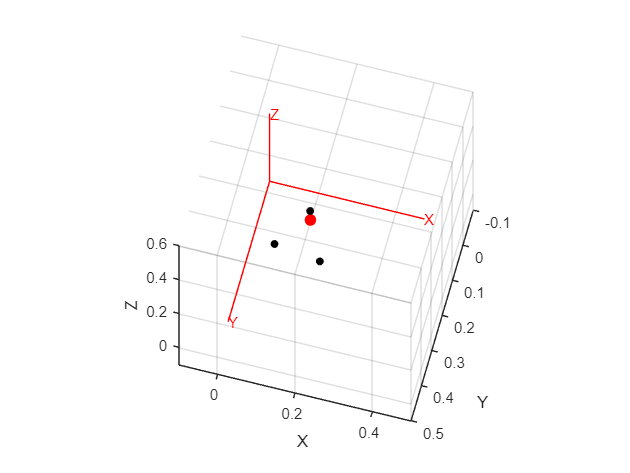

X2 = X * r;
Y2 = Y * r;
Z2 = Z * r; 
surf(X2+F1D(1),Y2+F1D(2),Z2+F1D(3),'FaceColor',[0 1 0])
surf(X2+F2D(1),Y2+F2D(2),Z2+F2D(3),'FaceColor',[0 1 0])
surf(X2+F3D(1),Y2+F3D(2),Z2+F3D(3),'FaceColor',[0 1 0])
surf(X*r2+Tumor(1),Y*r2+Tumor(2),Z*r2+Tumor(3),'FaceColor',[1 0 0], 'EdgeColor','none')

### T_F_I - Frame Description

% We construct the transformation to go from {F} to {I}, F1 is taken as 
% Pa_BORG where a is {F}
YfD = (F2D-F1D)/norm(F2D-F1D);
bD = (F3D-F1D)/norm(F3D-F1D);
ZfD = cross(YfD,bD)/norm(cross(YfD,bD));
XfD = cross(YfD,ZfD)/norm(cross(YfD,ZfD));

T_F_I = [[XfD;0] [YfD;0] [ZfD;0] [F1D;1]]

T_F_I = 4×4
    0.1698    0.9286   -0.3301    0.0700
    0.9226   -0.0320    0.3844    0.2140
    0.3464   -0.3698   -0.8621    0.1120
         0         0         0    1.0000



det(T_F_I)

ans = 1.0000

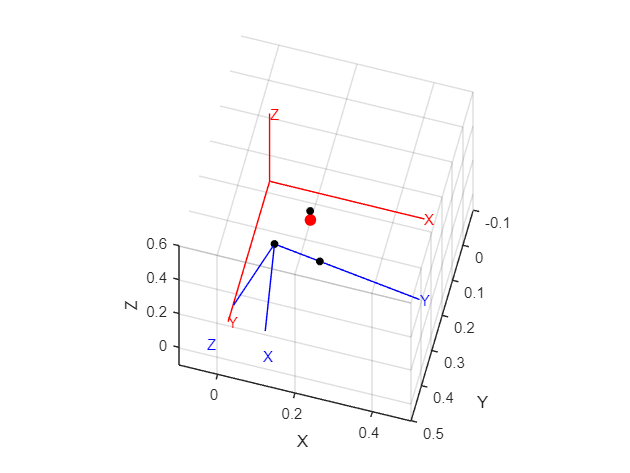

trplot(T_F_I,'Frame','F','color', 'b','length',0.4)


% We again check if Pu_FORG is coincident with the coordinate of fiducial1 in
% {U}
RPY=tr2rpy(T_F_I,'zyx')

RPY = 1×3
   -2.7364   -0.3537    1.3888


T_F_02=transl(F1D)*trotz(RPY(3))*troty(RPY(2))*trotx(RPY(1))

T_F_02 = 4×4
    0.1698    0.9286   -0.3301    0.0700
    0.9226   -0.0320    0.3844    0.2140
    0.3464   -0.3698   -0.8621    0.1120
         0         0         0    1.0000


T_F_I

T_F_I = 4×4
    0.1698    0.9286   -0.3301    0.0700
    0.9226   -0.0320    0.3844    0.2140
    0.3464   -0.3698   -0.8621    0.1120
         0         0         0    1.0000


### Image {I} reference frame wrt Univers {U} reference frame

% We put {I} with respect to {U}
T_I_0 = T_F_0*inv(T_F_I)

T_I_0 = 4×4
   -0.8660    0.0000   -0.5000    0.5457
    0.5000    0.0000   -0.8660    1.6098
   -0.0000   -1.0000   -0.0000    1.1300
         0         0         0    1.0000


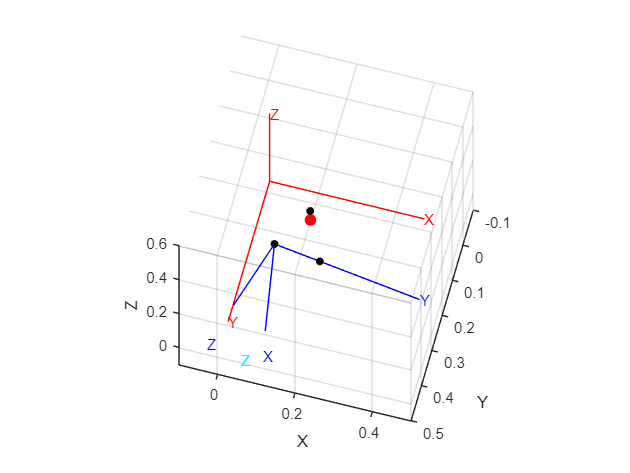

trplot(T_I_0,'Frame','I','color', 'cyan','length',0.7)

### T_I_R System equation

% We construct the transformation to go from {I} to {R}
T_I_p560 = inv(T_p560_0)*T_F_0*inv(T_F_I)

T_I_p560 = 4×4
   -0.0000   -0.0000    1.0000    0.7500
   -1.0000    0.0000   -0.0000    0.1275
   -0.0000   -1.0000   -0.0000    0.2500
         0         0         0    1.0000



% We check that with the given fiducials coordinates in image reference
% frame we can also obtain them in robot reference frame 
Fi_R2=T_I_p560*[[F1D F2D F3D];ones(1,3)]

Fi_R2 = 4×3
    0.8620    0.8158    0.7752
    0.0575   -0.0585    0.0055
    0.0360    0.0400    0.1860
    1.0000    1.0000    1.0000


Fi_R

Fi_R = 4×3
    0.8620    0.8158    0.7752
    0.0575   -0.0585    0.0055
    0.0360    0.0400    0.1860
    1.0000    1.0000    1.0000


### Fiducials in Universe Frame

% We check that with the given fiducials coordinates in image reference
% frame we can also obtain them in universe reference frame 
Fi_0=T_p560_0*T_I_p560*[[F1D F2D F3D];ones(1,3)]

Fi_0 = 4×3
    0.4291    0.3517    0.4275
    1.5478    1.6458    1.6490
    0.9160    0.9200    1.0660
    1.0000    1.0000    1.0000


Tumor_0=T_p560_0*T_I_p560*[Tumor;1]

Tumor_0 = 4×1
    0.4064
    1.6325
    1.0310
    1.0000


## Surgery (55%)

### Biospy

Prepare a script that perform a biopsy. Zoom in the scene and record a video with the best view.

Take into account:

- Use a tool that has the following Transformation: transl(0.05 0 0.25)

- Use 'trail' option of plot to visualize the trajectory.

- The speed of biopsy function that you design ought to be a parameter to satisfy the surgeons.

Answer these questions:

- Display in a figure the displacement, velocity and aceleration of the tool in End Efector Reference frame.

**Done at the bottom of this section**

- How much enter the tool in the patient brain.

**Taking into account that between images 112 and 78 there are 34 images, and between images there is a distance of 1.4mm, from the top of the skull to the center of the tumor there are 34 * 1.4mm = 47.6mm, what is equal to how much the tool enters in the patient brain.**

- What is the speed of the tool in World Reference Frame.

**Done at the bottom of this section**

% Now Biopsy, Trepanation and Burning will be done as before but using the
% information extracted from the position of the fiducials
close all

figure
hold on
patch('Vertices',v_tabla_0(1:3,:)','Faces',f,'FaceVertexCData',hsv(6),'FaceColor','black','FaceAlpha',0.4)
patch('Vertices',v_pata1_0(1:3,:)','Faces',f,'FaceVertexCData',hsv(6),'FaceColor','black','FaceAlpha',0.4)
patch('Vertices',v_pata2_0(1:3,:)','Faces',f,'FaceVertexCData',hsv(6),'FaceColor','black','FaceAlpha',0.4)
patch('Vertices',v_pata3_0(1:3,:)','Faces',f,'FaceVertexCData',hsv(6),'FaceColor','black','FaceAlpha',0.4)
patch('Vertices',v_pata4_0(1:3,:)','Faces',f,'FaceVertexCData',hsv(6),'FaceColor','black','FaceAlpha',0.4)
patch('Vertices',v_tablaherramientas_0(1:3,:)','Faces',f,'FaceVertexCData',hsv(6),'FaceColor','black','FaceAlpha',0.4)
patch('Vertices',v_pataherramientas_0(1:3,:)','Faces',f,'FaceVertexCData',hsv(6),'FaceColor','black','FaceAlpha',0.4)
patch('Vertices',v_humano_0(1:3,:)','Faces',Human.Fh,'FaceVertexCData',hsv(6),'FaceColor',[0.95,0.87,0.7], 'Edgecolor', 'none', 'FaceAlpha',0.8)
surf(X*r+Fi_0(1,1),Y*r+Fi_0(2,1),Z*r+Fi_0(3,1),'FaceColor',[1 0 0], 'EdgeColor','none')
surf(X*r+Fi_0(1,2),Y*r+Fi_0(2,2),Z*r+Fi_0(3,2),'FaceColor',[1 0 0], 'EdgeColor','none')
surf(X*r+Fi_0(1,3),Y*r+Fi_0(2,3),Z*r+Fi_0(3,3),'FaceColor',[1 0 0], 'EdgeColor','none')
surf(X*r2+Tumor_0(1,1),Y*r2+Tumor_0(2,1),Z*r2+Tumor_0(3,1),'FaceColor',[1 0 0], 'EdgeColor','none')
view(30,45)
grid on
xyzlabel
axis equal
axis([-2.5 2.5 -1.5 3.5 0.0 3.5])

% We set the appropriate tool to do the biopsy and then we set the frames
% that will divide our trajectories
p560.tool = transl(0.05,0,0.25)

 
p560 = 
 
Puma 560 [Unimation]:: 6 axis, RRRRRR, stdDH, slowRNE            
 - viscous friction; params of 8/95;                             
+---+-----------+-----------+-----------+-----------+-----------+
| j |     theta |         d |         a |     alpha |    offset |
+---+-----------+-----------+-----------+-----------+-----------+
|  1|         q1|          0|          0|     1.5708|          0|
|  2|         q2|          0|     0.4318|          0|          0|
|  3|         q3|    0.15005|     0.0203|    -1.5708|          0|
|  4|         q4|     0.4318|          0|     1.5708|          0|
|  5|         q5|          0|          0|    -1.5708|          0|
|  6|         q6|          0|          0|          0|          0|
+---+-----------+-----------+-----------+-----------+-----------+
base:    t = (0.81, 2.32, 0.88), RPY/xyz = (-120, 0, 0) deg      
tool:    t = (0.05, 0, 0.25), RPY/xyz = (0, 0, 0) deg            
 


T1 = [T_I_0(1:3,1:3) Tumor_0(1:3,:); 0 0 0 1]*transl(0.0,0.0,-0.3)*trotz(pi/2) % From robot initial pose to a distance = 0.3 from tumor

T1 = 4×4
    0.0000    0.8660   -0.5000    0.5564
    0.0000   -0.5000   -0.8660    1.8923
   -1.0000    0.0000   -0.0000    1.0310
         0         0         0    1.0000


T2 = [T_I_0(1:3,1:3) Tumor_0(1:3,:); 0 0 0 1]*trotz(pi/2) % From T1 final point to tumor

T2 = 4×4
    0.0000    0.8660   -0.5000    0.4064
    0.0000   -0.5000   -0.8660    1.6325
   -1.0000    0.0000   -0.0000    1.0310
         0         0         0    1.0000


T0 = p560.fkine(qr)

 

T0 = 
   -0.5000    0.8660         0    0.6452
   -0.8660   -0.5000         0     2.337
         0         0         1     1.994
         0         0         0         1


q_0 = p560.ikine6s(T0,'run');
q_1 = p560.ikine6s(T1,'run');
t_0 = linspace(0.0,3.0,30);
Q_0 = jtraj(q_0,q_1,t_0); % For the first trajectory we follow an eliptic path
t_1 = linspace(0.0,5.0,50);
S = tpoly(0,1,t_1);
S(1) = 0;
S(50) = 1;
T_1_2 = ctraj(T1,T2,S); % For the second trajectory we follow an straight path with non constant velocity
Q_1 = p560.ikine(T_1_2);
T_2_1 = ctraj(T2,T1,S); % We will perform a third trajectory that consists in returning to T1
Q_2 = p560.ikine(T_2_1);
QT = [Q_0;Q_1;Q_2];
p560.plot(QT,'zoom',2,'trail',{'r', 'LineWidth', 1.5});

### Displacement, velocity and aceleration of the tool in End Efector Reference frame

(Part of getting into the skull, the part of returning back would be the same but in reverse direction)

close all

t = t_1;
T_EEini_0 = T1;
T_EEact_0 = T_1_2;

% We convert world positions to end effector position with respect to
% initial end effector position
for i=1:50 
    T_EEact_EEini(:,:,i) = inv(T_EEini_0)*T_EEact_0(:,:,i);
end
figure
traj_points_xyz=transl(T_EEact_EEini);
velocity=diff(traj_points_xyz(:,:));
accel=diff(velocity);

% We plot the displacement, velocity and aceleration of the tool in End
% Effector Reference Frame
subplot(3,1,1)
plot(t,traj_points_xyz(:,:))
title('Displacement of the tool in EE RF')
ylabel('Positions')
xlabel('Time [s]')
legend('X','Y','Z')
subplot(3,1,2)
plot(t,[0 0 0; velocity])
title('Velocity of the tool in EE RF')
ylabel('Velocities')
xlabel('Time [s]')
legend('X','Y','Z')
subplot(3,1,3)
plot(t,[0 0 0; accel; 0 0 0])
title('Acceleration of the tool in EE RF')
ylabel('Accelerations')
xlabel('Time [s]')
legend('X','Y','Z')

### Speed of the tool in World Reference Frame

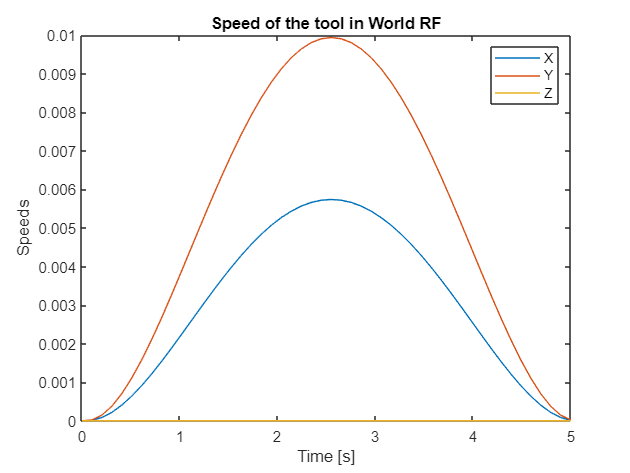

% Now we plot the speed of the tool in World Reference Frame
close all

t = t_1;
traj_points_xyz=transl(T_1_2);
velocity=abs(diff(traj_points_xyz(:,:)));

figure
subplot(1,1,1)
plot(t,[0 0 0; velocity])
title('Speed of the tool in World RF')
ylabel('Speeds');
xlabel('Time [s]');
legend('X','Y','Z');

### Trepanation

Prepare a script that perform trepanation. Zoom in the scene and record a video with the best view.

Take into account:

- Use a tool that has the following Transformation: transl(0 0 0.2)

- Use 'trail' option of plot to visualize the trajectory.

- Place a 45º cone on top of the trepanation to better understand. 

- See: 6_Plot_Box_Cone_fiducials.mlx. You will have to scale it. Play with transparency.

Answer these questions:

- Display in a figure the lineal displacement, velocity and aceleration of the tool in End Efector Reference frame.

- Display in a figure the manipulabitlity of the trepanation function either for translation and rotation.

- Find an alternate robot location for improving your manipulabitity.

**All done at the bottom of this section**

close all

% We plot a cone in top of the skull forming 45 degrees with its
% longitudinal axis 
Cono = load('F_V_Cone.mat')

Cono = struct with fields:
    fvc: [1×1 struct]


H = 0.2

H = 0.2000

W = 0.2

W = 0.2000

D = 0.2

D = 0.2000

v_cono = [H 0 0; 0 W 0; 0 0 D]*Cono.fvc.vertices';
v_cono(4,:) = 1;
T_cono_I = transl(0.132,0.099,-0.2)

T_cono_I = 4×4
    1.0000         0         0    0.1320
         0    1.0000         0    0.0990
         0         0    1.0000   -0.2000
         0         0         0    1.0000


T_cono_0 = T_I_0 * T_cono_I

T_cono_0 = 4×4
   -0.8660    0.0000   -0.5000    0.5314
    0.5000    0.0000   -0.8660    1.8490
   -0.0000   -1.0000   -0.0000    1.0310
         0         0         0    1.0000


v_cono_0 = T_cono_0 * v_cono;

figure
hold on
patch('Vertices',v_tabla_0(1:3,:)','Faces',f,'FaceVertexCData',hsv(6),'FaceColor','black','FaceAlpha',0.4)
patch('Vertices',v_pata1_0(1:3,:)','Faces',f,'FaceVertexCData',hsv(6),'FaceColor','black','FaceAlpha',0.4)
patch('Vertices',v_pata2_0(1:3,:)','Faces',f,'FaceVertexCData',hsv(6),'FaceColor','black','FaceAlpha',0.4)
patch('Vertices',v_pata3_0(1:3,:)','Faces',f,'FaceVertexCData',hsv(6),'FaceColor','black','FaceAlpha',0.4)
patch('Vertices',v_pata4_0(1:3,:)','Faces',f,'FaceVertexCData',hsv(6),'FaceColor','black','FaceAlpha',0.4)
patch('Vertices',v_cono_0(1:3,:)','Faces',Cono.fvc.faces,'FaceVertexCData',hsv(6),'FaceColor','b','FaceAlpha',0.2, 'EdgeColor','none')
patch('Vertices',v_tablaherramientas_0(1:3,:)','Faces',f,'FaceVertexCData',hsv(6),'FaceColor','black','FaceAlpha',0.4)
patch('Vertices',v_pataherramientas_0(1:3,:)','Faces',f,'FaceVertexCData',hsv(6),'FaceColor','black','FaceAlpha',0.4)
patch('Vertices',v_humano_0(1:3,:)','Faces',Human.Fh,'FaceVertexCData',hsv(6),'FaceColor',[0.95,0.87,0.7], 'Edgecolor', 'none', 'FaceAlpha',0.8)
surf(X*r+Fi_0(1,1),Y*r+Fi_0(2,1),Z*r+Fi_0(3,1),'FaceColor',[1 0 0], 'EdgeColor','none')
surf(X*r+Fi_0(1,2),Y*r+Fi_0(2,2),Z*r+Fi_0(3,2),'FaceColor',[1 0 0], 'EdgeColor','none')
surf(X*r+Fi_0(1,3),Y*r+Fi_0(2,3),Z*r+Fi_0(3,3),'FaceColor',[1 0 0], 'EdgeColor','none')
surf(X*r2+Tumor_0(1,1),Y*r2+Tumor_0(2,1),Z*r2+Tumor_0(3,1),'FaceColor',[1 0 0], 'EdgeColor','none')
view(30,45)
grid on
xyzlabel
axis equal
axis([-2.5 2.5 -1.5 3.5 0.0 3.5])

% We set the appropriate tool to do the trepanation and then we set the frames
% that will divide our trajectories
p560.tool = transl(0.0,0,0.2)

 
p560 = 
 
Puma 560 [Unimation]:: 6 axis, RRRRRR, stdDH, slowRNE            
 - viscous friction; params of 8/95;                             
+---+-----------+-----------+-----------+-----------+-----------+
| j |     theta |         d |         a |     alpha |    offset |
+---+-----------+-----------+-----------+-----------+-----------+
|  1|         q1|          0|          0|     1.5708|          0|
|  2|         q2|          0|     0.4318|          0|          0|
|  3|         q3|    0.15005|     0.0203|    -1.5708|          0|
|  4|         q4|     0.4318|          0|     1.5708|          0|
|  5|         q5|          0|          0|    -1.5708|          0|
|  6|         q6|          0|          0|          0|          0|
+---+-----------+-----------+-----------+-----------+-----------+
base:    t = (0.81, 2.32, 0.88), RPY/xyz = (-120, 0, 0) deg      
tool:    t = (0, 0, 0.2), RPY/xyz = (0, 0, 0) deg                
 


T1 = [T_I_0(1:3,1:3) Tumor_0(1:3,:); 0 0 0 1]*transl(0.0,-0.00725,-0.05)*trotz(pi/2)*troty(pi/4) % From robot initial pose to first trepanation point

T1 = 4×4
    0.3536    0.8660   -0.3536    0.4314
    0.6124   -0.5000   -0.6124    1.6758
   -0.7071    0.0000   -0.7071    1.0383
         0         0         0    1.0000


T0 = p560.fkine(qr)

 

T0 = 
   -0.5000    0.8660         0    0.6702
   -0.8660   -0.5000         0     2.381
         0         0         1     1.944
         0         0         0         1


q_0 = p560.ikine6s(T0,'run');
q_1 = p560.ikine6s(T1,'run');
t_0 = linspace(0.0,3.0,30);
% We do the trepanation always perforing the skull with 45 degrees wrt the
% longitudinal axis of the human
for i=1:50
Trepanation_Pose(:,:,i)= [T_I_0(1:3,1:3) Tumor_0(1:3,:); 0 0 0 1]*transl(0.0,0.0,-0.05)*trotz((2*pi*i/50)+pi/2)*transl(0.0,-0.00725,0)*troty(pi/4);
end
Q_0 = jtraj(q_0,q_1,t_0); % For the first trajectory we follow an eliptic path
Q_1 = p560.ikine6s(Trepanation_Pose, 'run'); % For the trepanation we follow constant velocity
Q_2 = jtraj(q_1,q_0,t_0) % We return to initial position

Q_2 = 30×6
    0.2417    1.1693   -2.9214    2.8538    0.6389   -2.7357
    0.2416    1.1695   -2.9208    2.8539    0.6386   -2.7334
    0.2410    1.1705   -2.9174    2.8546    0.6370   -2.7183
    0.2395    1.1731   -2.9086    2.8565    0.6329   -2.6803
    0.2366    1.1778   -2.8929    2.8599    0.6254   -2.6116
    0.2323    1.1850   -2.8688    2.8650    0.6140   -2.5070
    0.2264    1.1948   -2.8358    2.8720    0.5984   -2.3633
    0.2189    1.2073   -2.7936    2.8810    0.5784   -2.1795
    0.2097    1.2226   -2.7422    2.8920    0.5541   -1.9561
    0.1989    1.2404   -2.6823    2.9047    0.5258   -1.6952


QT = [Q_0;Q_1;Q_2];
p560.plot(QT,'zoom',2,'trail',{'r', 'LineWidth', 1.5});

### Displacement, velocity and aceleration of the tool in End Efector Reference frame

(Part of perforing the skull)

close all
ts = 0.1

ts = 0.1000

tf = 5

tf = 5

t = (0:ts:tf-ts)

t = 1×50
         0    0.1000    0.2000    0.3000    0.4000    0.5000    0.6000    0.7000    0.8000    0.9000    1.0000    1.1000    1.2000    1.3000    1.4000    1.5000    1.6000    1.7000    1.8000    1.9000    2.0000    2.1000    2.2000    2.3000    2.4000    2.5000    2.6000    2.7000    2.8000    2.9000


T_EEini_0 = T1

T_EEini_0 = 4×4
    0.3536    0.8660   -0.3536    0.4314
    0.6124   -0.5000   -0.6124    1.6758
   -0.7071    0.0000   -0.7071    1.0383
         0         0         0    1.0000


T_EEact_0 = Trepanation_Pose

T_EEact_0 = T_EEact_0(:,:,1) =

    0.4303    0.8592   -0.2768    0.4252
    0.5681   -0.4961   -0.6567    1.6794
   -0.7015    0.1253   -0.7015    1.0301
         0         0         0    1.0000


T_EEact_0(:,:,2) =

    0.5058    0.8388   -0.2013    0.4253
    0.5244   -0.4843   -0.7003    1.6793
   -0.6849    0.2487   -0.6849    1.0292
         0         0         0    1.0000


T_EEact_0(:,:,3) =

    0.5790    0.8052   -0.1281    0.4256
    0.4822   -0.4649   -0.7425    1.6792
   -0.6575    0.3681   -0.6575    1.0283
         0         0         0    1.0000


T_EEact_0(:,:,4) =

    0.6486    0.7589   -0.0585    0.4259
    0.4420   -0.4382   -0.7827    1.6790
   -0.6196    0.4818   -0.6196    1.0275
         0         0         0    1.0000


T_EEact_0(:,:,5) =

    0.7135    0.7006    0.0064    0.4263
    0.4046   -0.4045   -0.8202    1.6787
   -0.5721    0.5878   -0.5721    1.0267
         0         0         0    1.0000


T_EEact_0(:,:,6) =

    0.7728    0.6313    0.0656    0.42

T_EEact_EEini = []


T_EEact_EEini =

     []



for i=1:50 
    T_EEact_EEini(:,:,i) = inv(T_EEini_0)*T_EEact_0(:,:,i);
end
figure
traj_points_xyz=transl(T_EEact_EEini)

traj_points_xyz = 50×3
    0.0058   -0.0072    0.0058
    0.0064   -0.0070    0.0064
    0.0070   -0.0067    0.0070
    0.0076   -0.0064    0.0076
    0.0081   -0.0059    0.0081
    0.0086   -0.0053    0.0086
    0.0091   -0.0046    0.0091
    0.0095   -0.0039    0.0095
    0.0098   -0.0031    0.0098
    0.0100   -0.0022    0.0100


velocity=diff(traj_points_xyz(:,:))

velocity = 49×3
1.0e-03 *

    0.6324    0.1706    0.6324
    0.6123    0.2813    0.6123
    0.5825    0.3877    0.5825
    0.5436    0.4879    0.5436
    0.4961    0.5804    0.4961
    0.4407    0.6637    0.4407
    0.3784    0.7366    0.3784
    0.3102    0.7978    0.3102
    0.2370    0.8465    0.2370
    0.1601    0.8819    0.1601


accel=diff(velocity)

accel = 48×3
1.0e-03 *

   -0.0201    0.1107   -0.0201
   -0.0298    0.1063   -0.0298
   -0.0389    0.1002   -0.0389
   -0.0475    0.0925   -0.0475
   -0.0553    0.0833   -0.0553
   -0.0623    0.0729   -0.0623
   -0.0683    0.0613   -0.0683
   -0.0732    0.0487   -0.0732
   -0.0769    0.0353   -0.0769
   -0.0794    0.0214   -0.0794


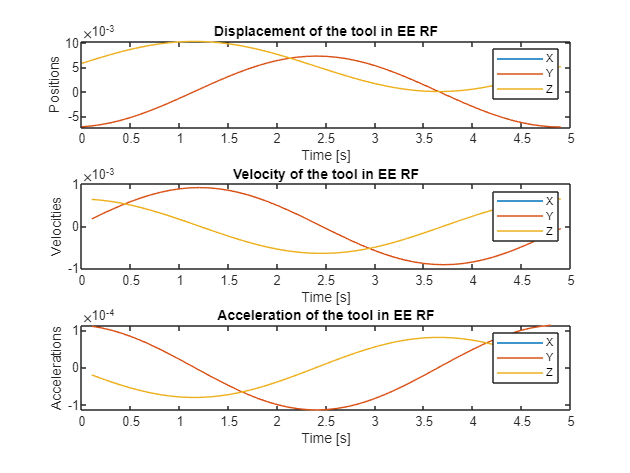


subplot(3,1,1)
plot(t,traj_points_xyz(:,:))
title('Displacement of the tool in EE RF')
ylabel('Positions')
xlabel('Time [s]')
legend('X','Y','Z')
subplot(3,1,2)
plot(t(2:50),velocity)
title('Velocity of the tool in EE RF')
ylabel('Velocities')
xlabel('Time [s]')
legend('X','Y','Z')
subplot(3,1,3)
plot(t(2:49),accel)
title('Acceleration of the tool in EE RF')
ylabel('Accelerations')
xlabel('Time [s]')
legend('X','Y','Z')

### Manipulability

% Although qn configuration has a better manipulability than the others, we
% have seen that qr was the one that worked better for our case, so we have
% chosen qn
m1 = p560.maniplty(qr)

m1 = 0

m2=p560.maniplty(qn)

m2 = 0.0786

m3=p560.maniplty(qs)

m3 = 9.7886e-11

m4=p560.maniplty(qz)

m4 = 0

### Tumor burning

Prepare a script that perform tumor burning with the laser.  Zoom in the scene and record a video with the best view.

You ought to think in an algorithm, that in order, fill up the tumor's  equivalent sphere with small burning spheres of 4mm diameter.

Use a tool that has the following Transformation: transl(0 0 0.2)

Answer these questions:

- Display in a figure the lineal displacement, velocity and aceleration of the tool in End Efector Reference frame.

**Done at the bottom of this section**

- How long it takes your burning function to burn the tumor

**Our burning function takes 16.5 seconds to burn the tumor as we define a trajectory that lasts 0.5 seconds between each tumor point and we have 33 tumor points. If we also consider the trajectory of going from robot initial pose to in front of the skull, the trajectory of going from in front of the skull to the small hole made and the trajectory of returning back from there, all together lasts 3 + 5 + 16.5 + 5 = 29.5 seconds **

close all

figure
hold on

% We plot the tumor subdivided in little spheres with radius = 4mm
esferas = zeros(33, 3)

esferas = 33×3
     0     0     0
     0     0     0
     0     0     0
     0     0     0
     0     0     0
     0     0     0
     0     0     0
     0     0     0
     0     0     0
     0     0     0


i = 1

i = 1

rpeq = 0.004;
rgran = 0.0145;
[x, y, z] = sphere;
w = linspace(-rgran + rpeq, rgran - rpeq, 4);
light('Position',[2 3 1])

for ix = w
   for iy = w
      for iz = w
          if (ix)^2 + (iy)^2 + (iz)^2 < rgran^2

              esferas(i,:) = [ix iy iz];
              surf(x * rpeq + ix + Tumor_0(1,1), y * rpeq + iy + Tumor_0(2,1), z * rpeq + iz + Tumor_0(3,1),...
                  'FaceColor',[1 0 0], 'EdgeColor','none', 'FaceLighting', 'gouraud');
              i = i + 1;

          end
      end
   end
end

patch('Vertices',v_tabla_0(1:3,:)','Faces',f,'FaceVertexCData',hsv(6),'FaceColor','black','FaceAlpha',0.4)
patch('Vertices',v_pata1_0(1:3,:)','Faces',f,'FaceVertexCData',hsv(6),'FaceColor','black','FaceAlpha',0.4)
patch('Vertices',v_pata2_0(1:3,:)','Faces',f,'FaceVertexCData',hsv(6),'FaceColor','black','FaceAlpha',0.4)
patch('Vertices',v_pata3_0(1:3,:)','Faces',f,'FaceVertexCData',hsv(6),'FaceColor','black','FaceAlpha',0.4)
patch('Vertices',v_pata4_0(1:3,:)','Faces',f,'FaceVertexCData',hsv(6),'FaceColor','black','FaceAlpha',0.4)
patch('Vertices',v_tablaherramientas_0(1:3,:)','Faces',f,'FaceVertexCData',hsv(6),'FaceColor','black','FaceAlpha',0.4)
patch('Vertices',v_pataherramientas_0(1:3,:)','Faces',f,'FaceVertexCData',hsv(6),'FaceColor','black','FaceAlpha',0.4)
patch('Vertices',v_humano_0(1:3,:)','Faces',Human.Fh,'FaceVertexCData',hsv(6),'FaceColor',[0.95,0.87,0.7], 'Edgecolor', 'none', 'FaceAlpha',0.4)
surf(X*r+Fi_0(1,1),Y*r+Fi_0(2,1),Z*r+Fi_0(3,1),'FaceColor',[1 0 0], 'EdgeColor','none')
surf(X*r+Fi_0(1,2),Y*r+Fi_0(2,2),Z*r+Fi_0(3,2),'FaceColor',[1 0 0], 'EdgeColor','none')
surf(X*r+Fi_0(1,3),Y*r+Fi_0(2,3),Z*r+Fi_0(3,3),'FaceColor',[1 0 0], 'EdgeColor','none')
view(30,45)
grid on
xyzlabel
axis equal
axis([-2.5 2.5 -1.5 3.5 0.0 3.5])

% We set the appropriate tool to do the burning and then we set the frames
% that will divide our trajectories
p560.tool = transl(0.0,0,0.2)

 
p560 = 
 
Puma 560 [Unimation]:: 6 axis, RRRRRR, stdDH, slowRNE            
 - viscous friction; params of 8/95;                             
+---+-----------+-----------+-----------+-----------+-----------+
| j |     theta |         d |         a |     alpha |    offset |
+---+-----------+-----------+-----------+-----------+-----------+
|  1|         q1|          0|          0|     1.5708|          0|
|  2|         q2|          0|     0.4318|          0|          0|
|  3|         q3|    0.15005|     0.0203|    -1.5708|          0|
|  4|         q4|     0.4318|          0|     1.5708|          0|
|  5|         q5|          0|          0|    -1.5708|          0|
|  6|         q6|          0|          0|          0|          0|
+---+-----------+-----------+-----------+-----------+-----------+
base:    t = (0.81, 2.32, 0.88), RPY/xyz = (-120, 0, 0) deg      
tool:    t = (0, 0, 0.2), RPY/xyz = (0, 0, 0) deg                
 


T1 = [T_I_0(1:3,1:3) Tumor_0(1:3,:); 0 0 0 1]*transl(0.0,0.0,-0.3)*trotz(pi/2) % From robot initial pose to first trepanation point

T1 = 4×4
    0.0000    0.8660   -0.5000    0.5564
    0.0000   -0.5000   -0.8660    1.8923
   -1.0000    0.0000   -0.0000    1.0310
         0         0         0    1.0000


T0 = p560.fkine(qr)

 

T0 = 
   -0.5000    0.8660         0    0.6702
   -0.8660   -0.5000         0     2.381
         0         0         1     1.944
         0         0         0         1


q_0 = p560.ikine6s(T0,'run');
q_1 = p560.ikine6s(T1,'run');
t_0 = linspace(0.0,3.0,30);
Q_0 = jtraj(q_0,q_1,t_0); % For the first trajectory we follow an eliptic path

T_ini = [T_I_0(1:3,1:3) Tumor_0(1:3,:); 0 0 0 1]*transl(0.0,0.0,-0.075)*trotz(pi/2)

T_ini = 4×4
    0.0000    0.8660   -0.5000    0.4439
    0.0000   -0.5000   -0.8660    1.6975
   -1.0000    0.0000   -0.0000    1.0310
         0         0         0    1.0000


t_1 = linspace(0.0,5.0,50);
S = tpoly(0,1,t_1);
S(1) = 0;
S(50) = 1;
T_1_ini = ctraj(T1,T_ini,S); % For the second trajectory we follow an straight path with non constant velocity
Q_1 = p560.ikine(T_1_ini);
p560.plot([Q_0;Q_1],'zoom',2,'trail',{'r', 'LineWidth', 1.5});

q_ini = p560.ikine6s(T_ini);
t_2 = linspace(0.0,0.5,5);

% Between each point to burn we create a trajectory, so we point one sphere
% and then we move the tool rotating it to point another
for i=1:33
    
    dy = sqrt((0.0-esferas(i,1))^2 + (-0.075-esferas(i,2))^2);
    dx = sqrt((0.0-esferas(i,3))^2 + (-0.075-esferas(i,2))^2);
    ax = asin(esferas(i,1)/dy);
    ay = asin(esferas(i,3)/dx);
    T_i = [T_I_0(1:3,1:3) Tumor_0(1:3,:); 0 0 0 1]*transl(0.0,0.0,-0.075)*trotz(pi/2)*trotx(-ax)*troty(-ay);
    Burning_Pose(:,:,i)=T_i;
    q_i = p560.ikine6s(T_i, 'lun');
    Q_i = jtraj(q_ini,q_i,t_2);
    p560.plot(Q_i,'zoom',2,'trail',{'r', 'LineWidth', 1.5});
    surf(x * rpeq + esferas(i,1) + Tumor_0(1,1), y * rpeq + esferas(i,2) + Tumor_0(2,1), z * rpeq + esferas(i,3) + Tumor_0(3,1),...
                  'FaceColor','#006400', 'EdgeColor','none', 'FaceLighting', 'gouraud');
    q_ini = q_i;
end

T_ini_1 = ctraj(T_ini, T1, S); % Finally we return to T1 with a cartesian trajectory
Q_2 = p560.ikine(T_ini_1);
p560.plot(Q_2,'zoom',2,'trail',{'r', 'LineWidth', 1.5});

### Displacement, velocity and aceleration of the tool in End Efector Reference frame

(Part of going to the entry of the skull, then the tool only rotates with respect to x and y axis of end effector reference frame to burn the tumor)

close all

t = t_1;
T_EEini_0 = T1

T_EEini_0 = 4×4
    0.0000    0.8660   -0.5000    0.5564
    0.0000   -0.5000   -0.8660    1.8923
   -1.0000    0.0000   -0.0000    1.0310
         0         0         0    1.0000


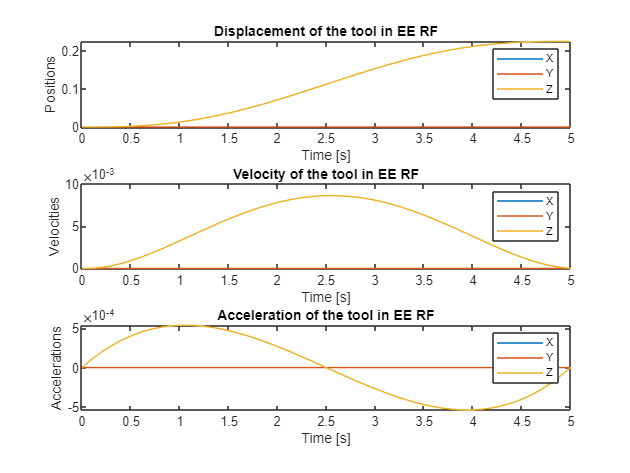

T_EEact_0 = T_1_ini;
T_EEact_EEini = [];
for i=1:50 
    T_EEact_EEini(:,:,i) = inv(T_EEini_0)*T_EEact_0(:,:,i);
end
figure
traj_points_xyz=transl(T_EEact_EEini);
velocity=diff(traj_points_xyz(:,:));
accel=diff(velocity);

subplot(3,1,1)
plot(t,traj_points_xyz(:,:))
title('Displacement of the tool in EE RF')
ylabel('Positions')
xlabel('Time [s]')
legend('X','Y','Z')
subplot(3,1,2)
plot(t,[0 0 0; velocity])
title('Velocity of the tool in EE RF')
ylabel('Velocities')
xlabel('Time [s]')
legend('X','Y','Z')
subplot(3,1,3)
plot(t,[0 0 0; accel; 0 0 0])
title('Acceleration of the tool in EE RF')
ylabel('Accelerations')
xlabel('Time [s]')
legend('X','Y','Z')